##  ECE 537 : Assignment 3

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

%dimensions
K = 1000;
D = 3;

%mean
mu_A = [0 4 7];
mu_B = [10 5 5];
mu_C = [-2 -5 -5];

%covariance
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];

%data
data_A = gaussian_data(K,D,mu_A,sigma_A);
data_B = gaussian_data(K,D,mu_B,sigma_B);
data_C = gaussian_data(K,D,mu_C,sigma_C);

Npt = 200;
%3d volume of regular grid points
V = vol3D([-15 20 -15 20 -15 20],Npt);
%priori probabilities 
pwA = 0.3;
pwB = 0.3;
pwC = 0.3;

%likelihood
pxwA = gaussian_density(mu_A,sigma_A,V);
pxwB = gaussian_density(mu_B,sigma_B,V);
pxwC = gaussian_density(mu_C,sigma_C,V);

%evidence
px = pxwA*pwA + pxwB*pwB + pxwC*pwC; %evidence

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;
pwCx = (pxwC*pwC)./px;

**Task 1: **Use Matlab's neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.

Solution: 

data = [data_A;data_B;data_C]; %total data
targets = [ones(1000,1);2*ones(1000,1);3*ones(1000,1)]; %corresponding labels
train_test_split  = 0.7;
hidden_layer = 10

hidden_layer = 10

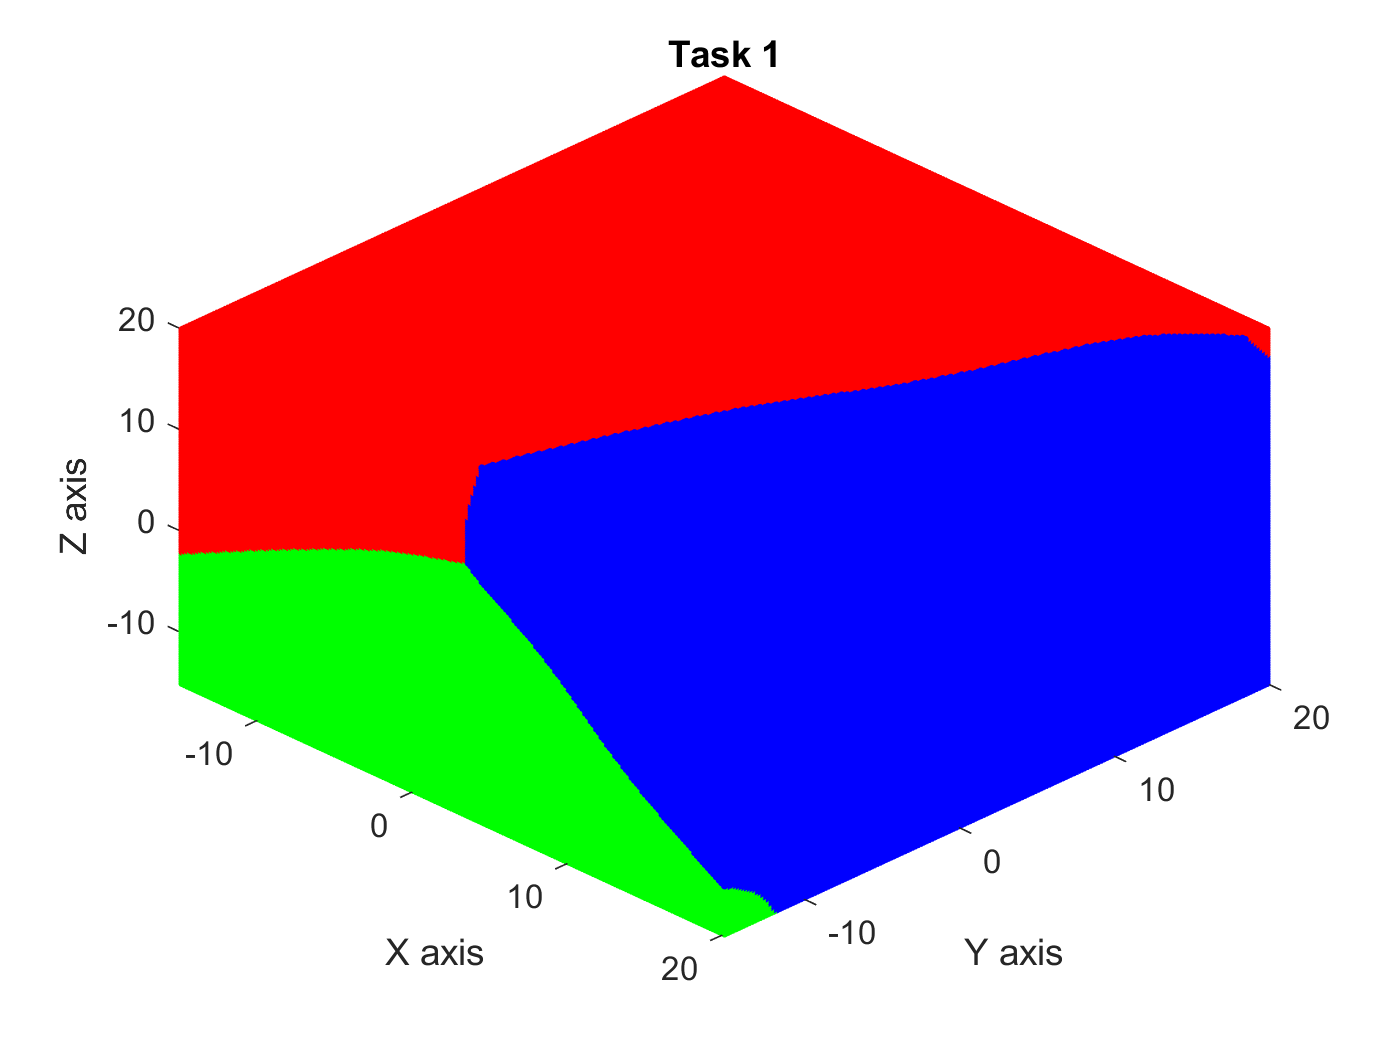

target_new = bsxfun(@eq, targets(:), 1:max(targets));
s = 1; %seed
[class_index,e,performance] = nn__classifier(data,targets,V,train_test_split,hidden_layer,s);
visualize_points(class_index,V);
title('Task 1')

**Task 2: **Plot the decision boundaries created by this trained neural network classifier and discuss the "correctness" of these boundaries versus the Bayesian class boundaries that were generated in Exercise 2

Solution:

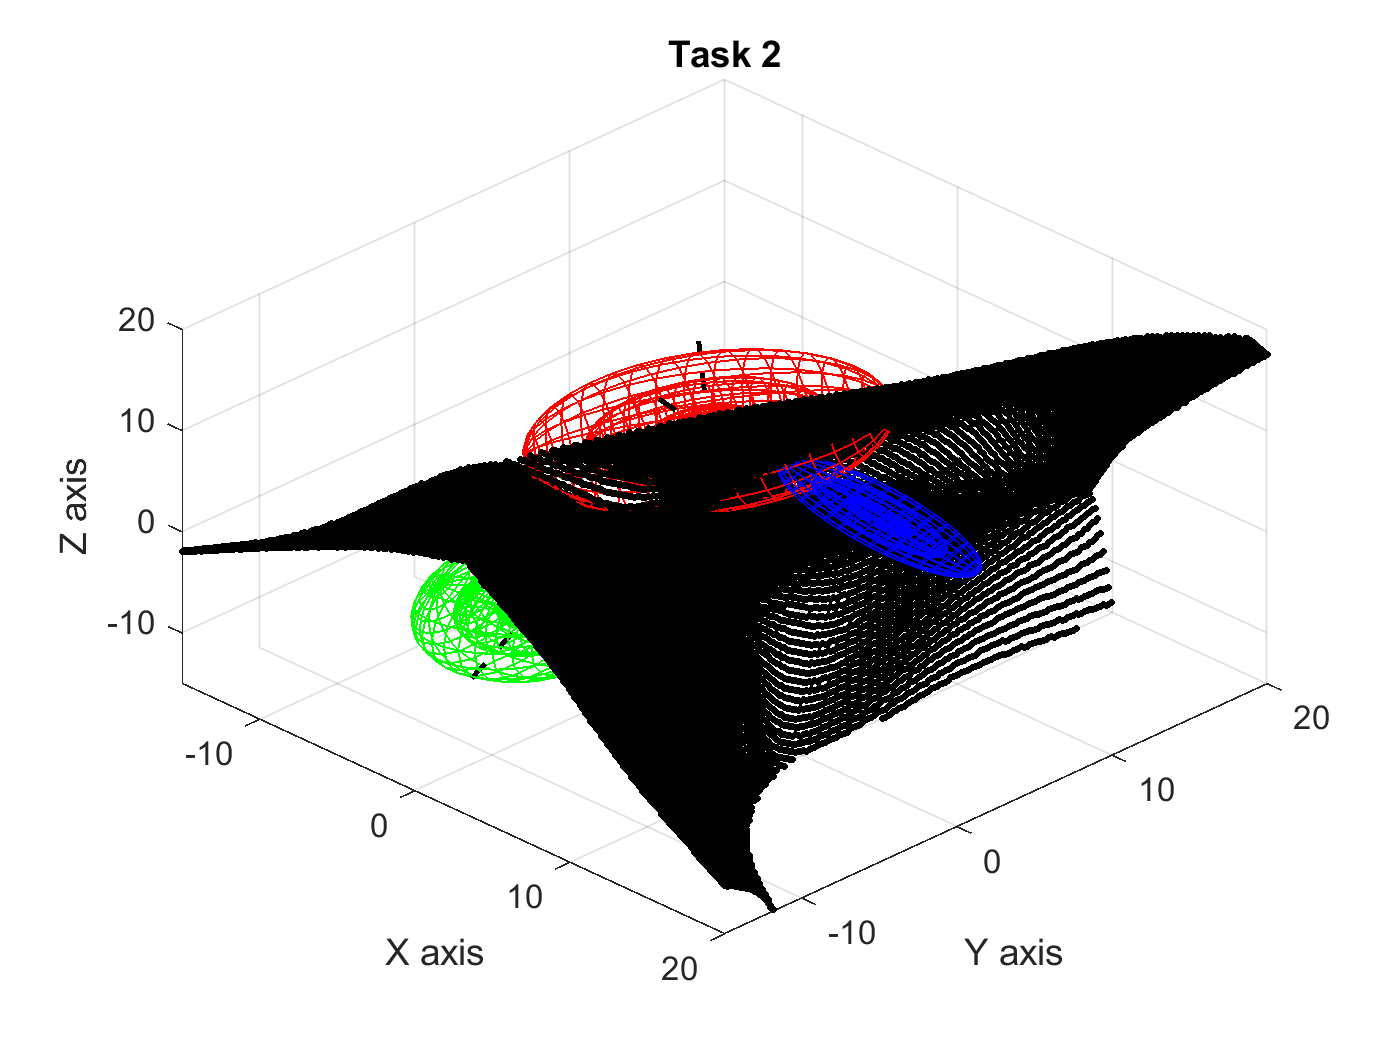

figure(2);
b = decision_boundary(V,Npt,class_index);
visualize_boundary(data_A, data_B, data_C, b);
title('Task 2')

Neural networks can construct arbitrary decision boundaries without assuming any underlying probability density function. As a result , the classifier will try to asymptotically approach bayes decision boundary. Since the neural network is subjected to random initialization (different starting points for each simulation) i.e. training multiple times will generate different results due to different initial conditions and sampling. Also the classification accuracy for the training data is < 100% which indicates the decision boundary obtained using the outputs from neural network will be less correct as with respect to the bayes decision bounday where the underlying probably distribution of the class A, class B and class C is known.

**Task 3: **Discuss whether or not (and why) Matlab's computation of the trained neural network's error, as implemented within its neural net toolbox, is correct.

Solution: 

%Computing the mean squared error for the neural network classifier
[max_error,~] = max(abs(e));
MSE=  sum(max_error.*max_error,2)/length(max_error)

MSE = 0.0034

performance

performance = 0.0044

The computed mean squared error is slighlty differs from the performance of the network which is calculated from the trained neural network error. This indicates that the Matlab's computation of trained neural network error can be accepted.

**Task 4** - Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries.

Solution:

Since the neural network is subjected to random initialization (different starting points for each simulation) i.e. training multiple times will generate different results due to different initial conditions and sampling.

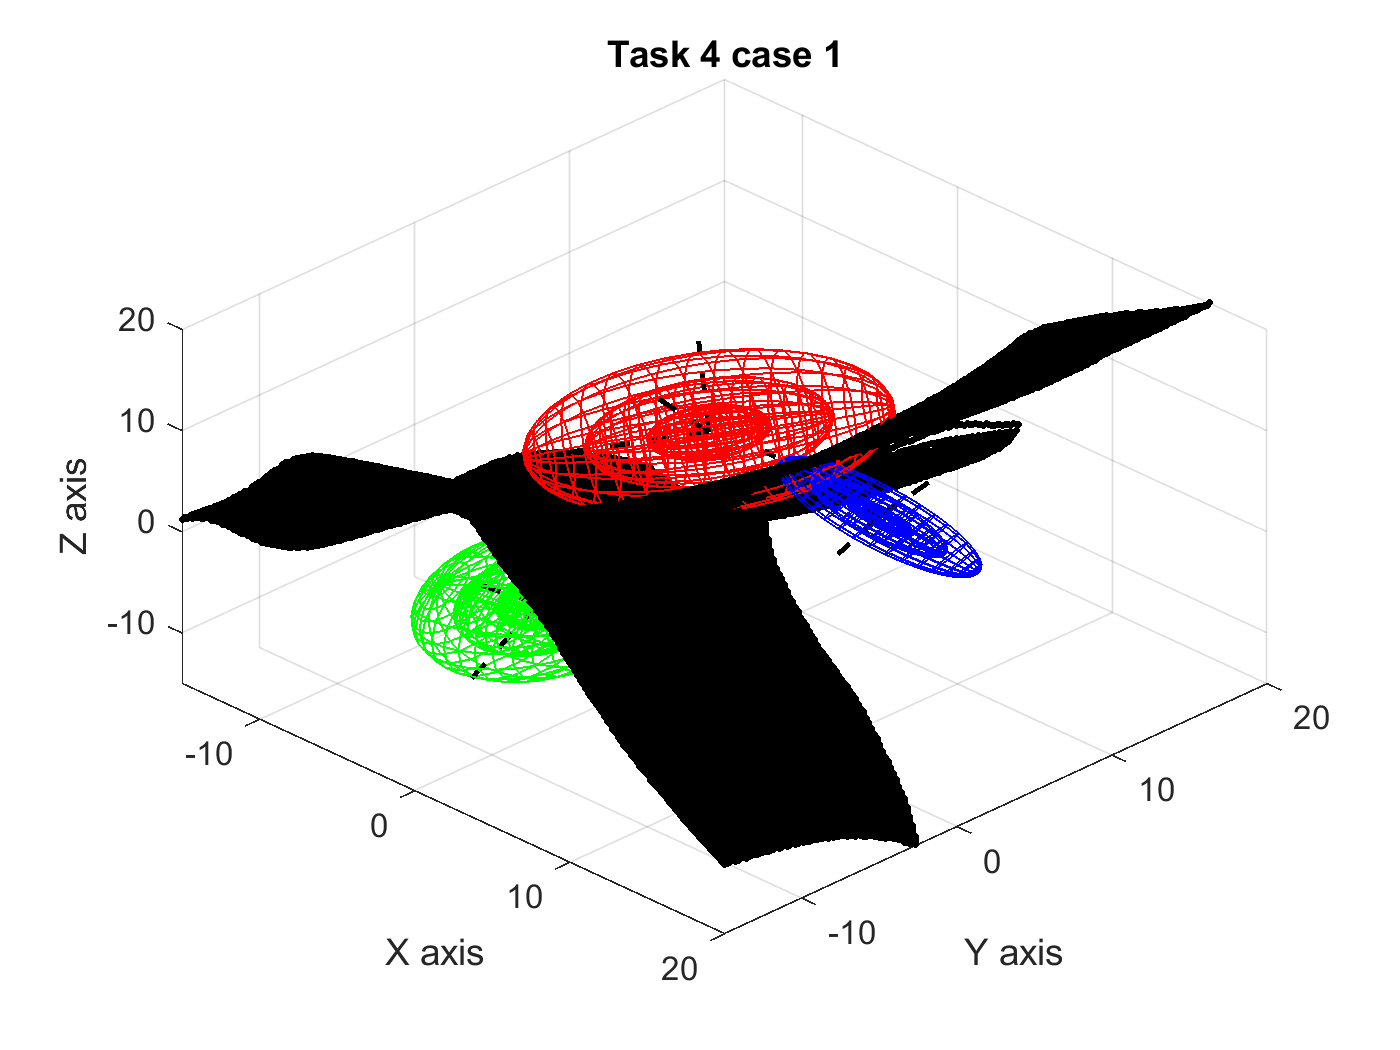

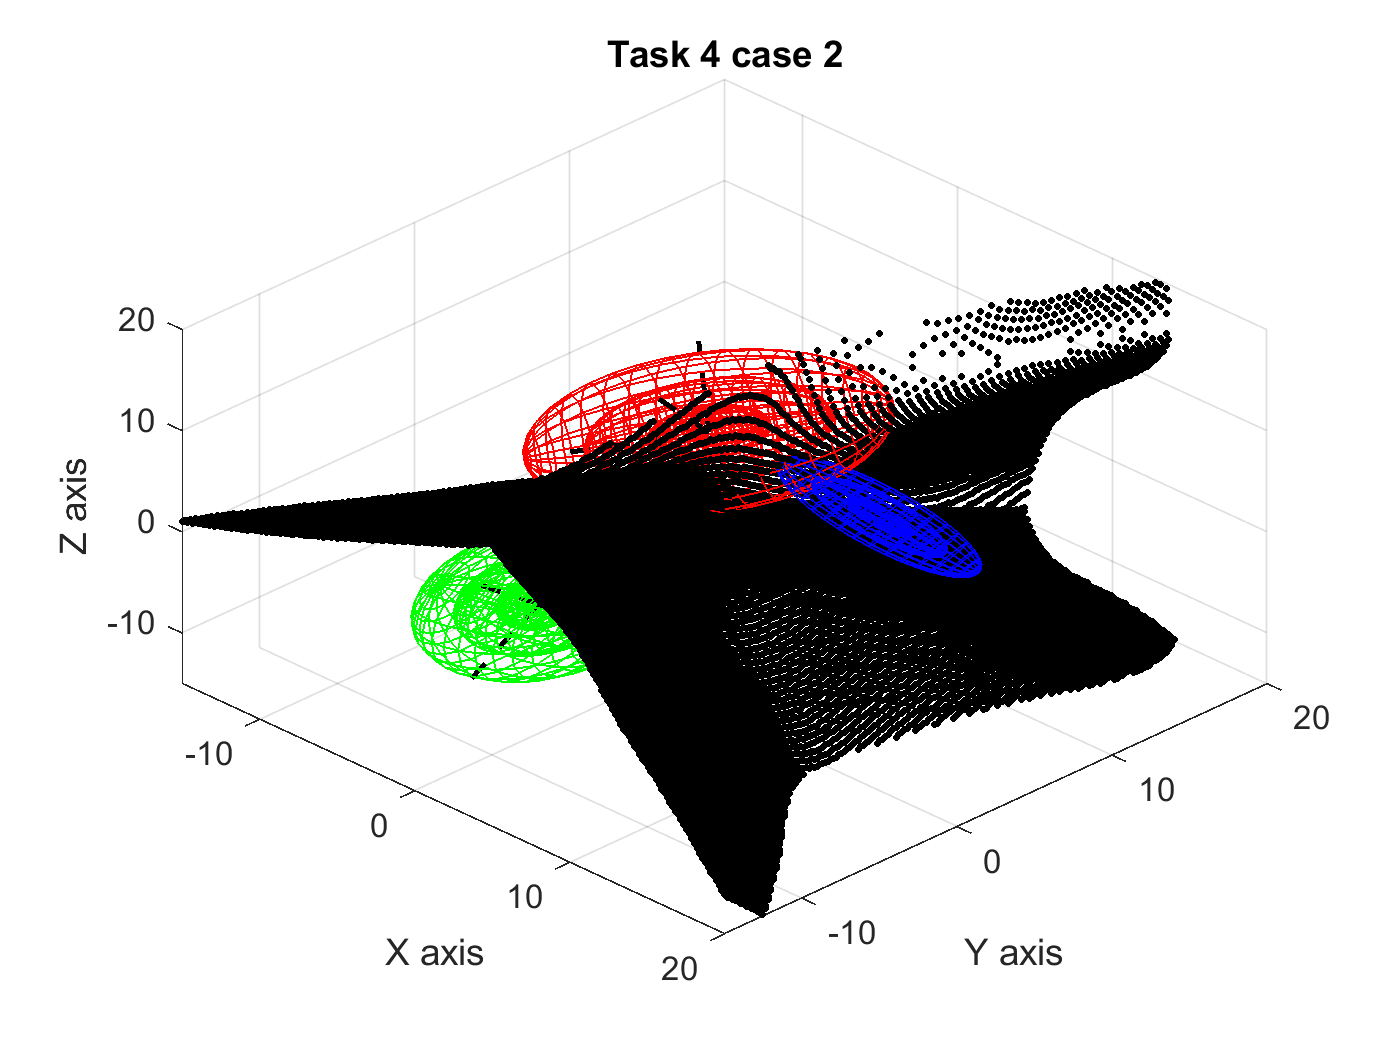

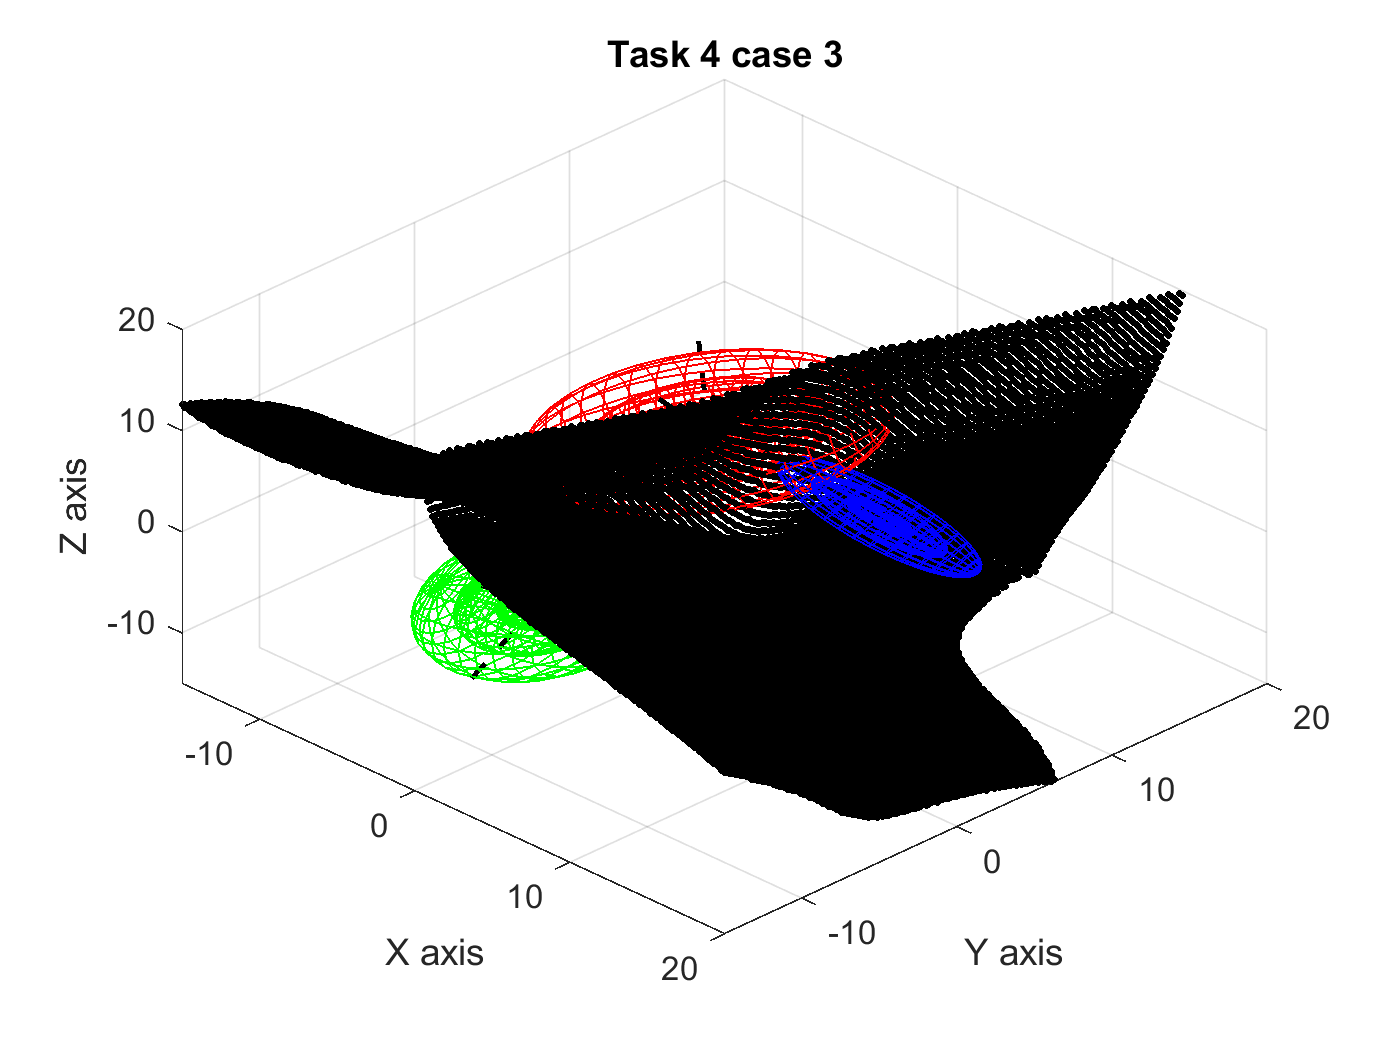

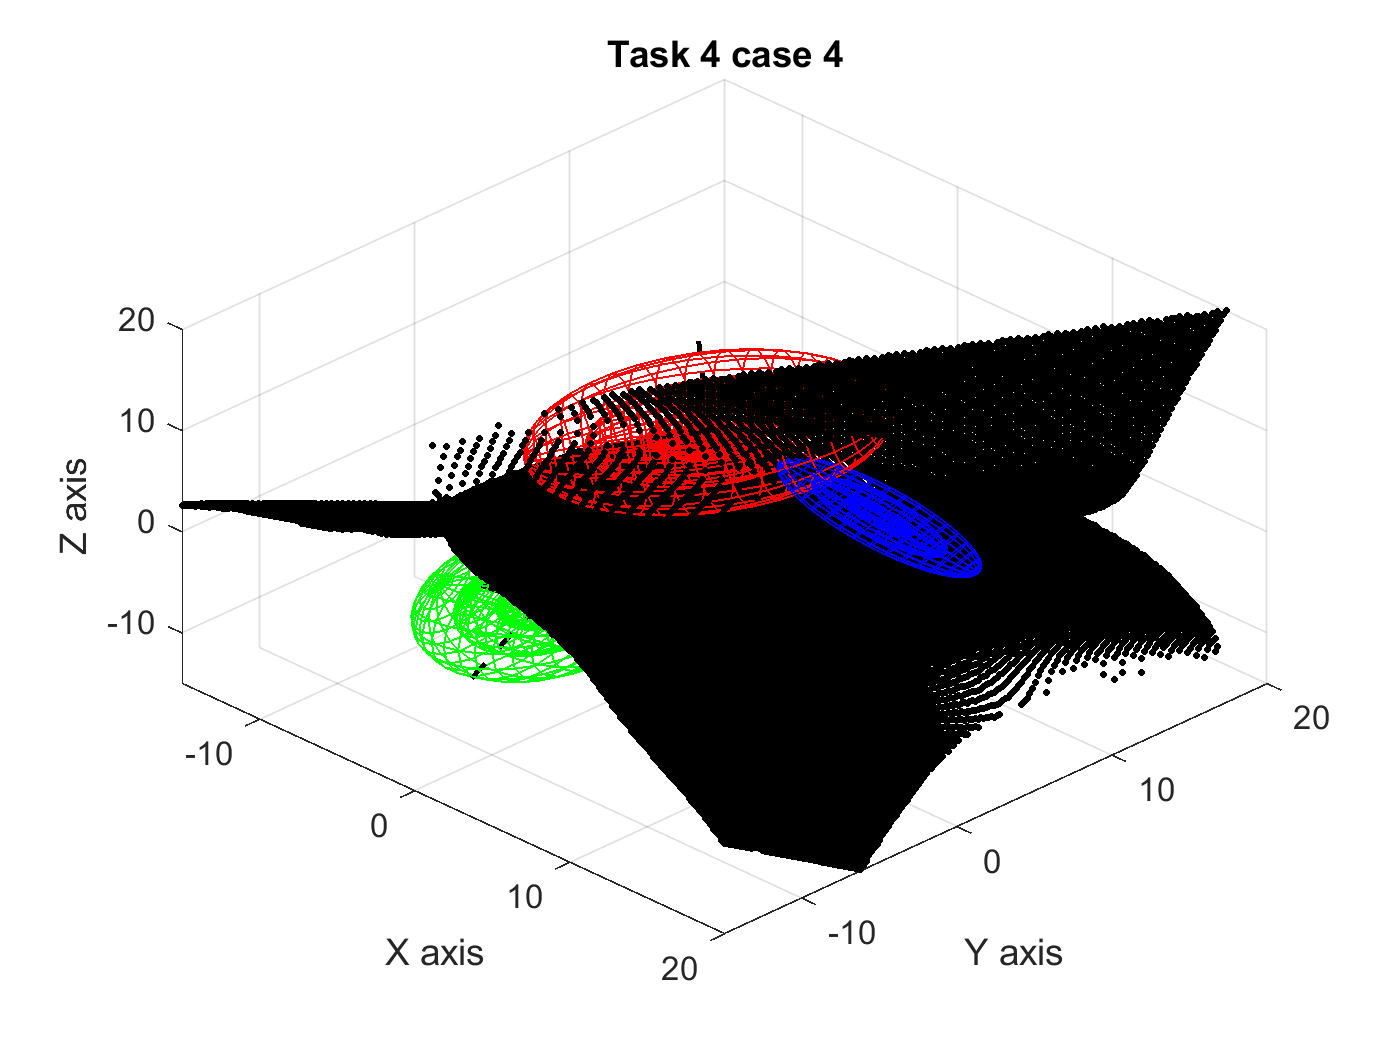

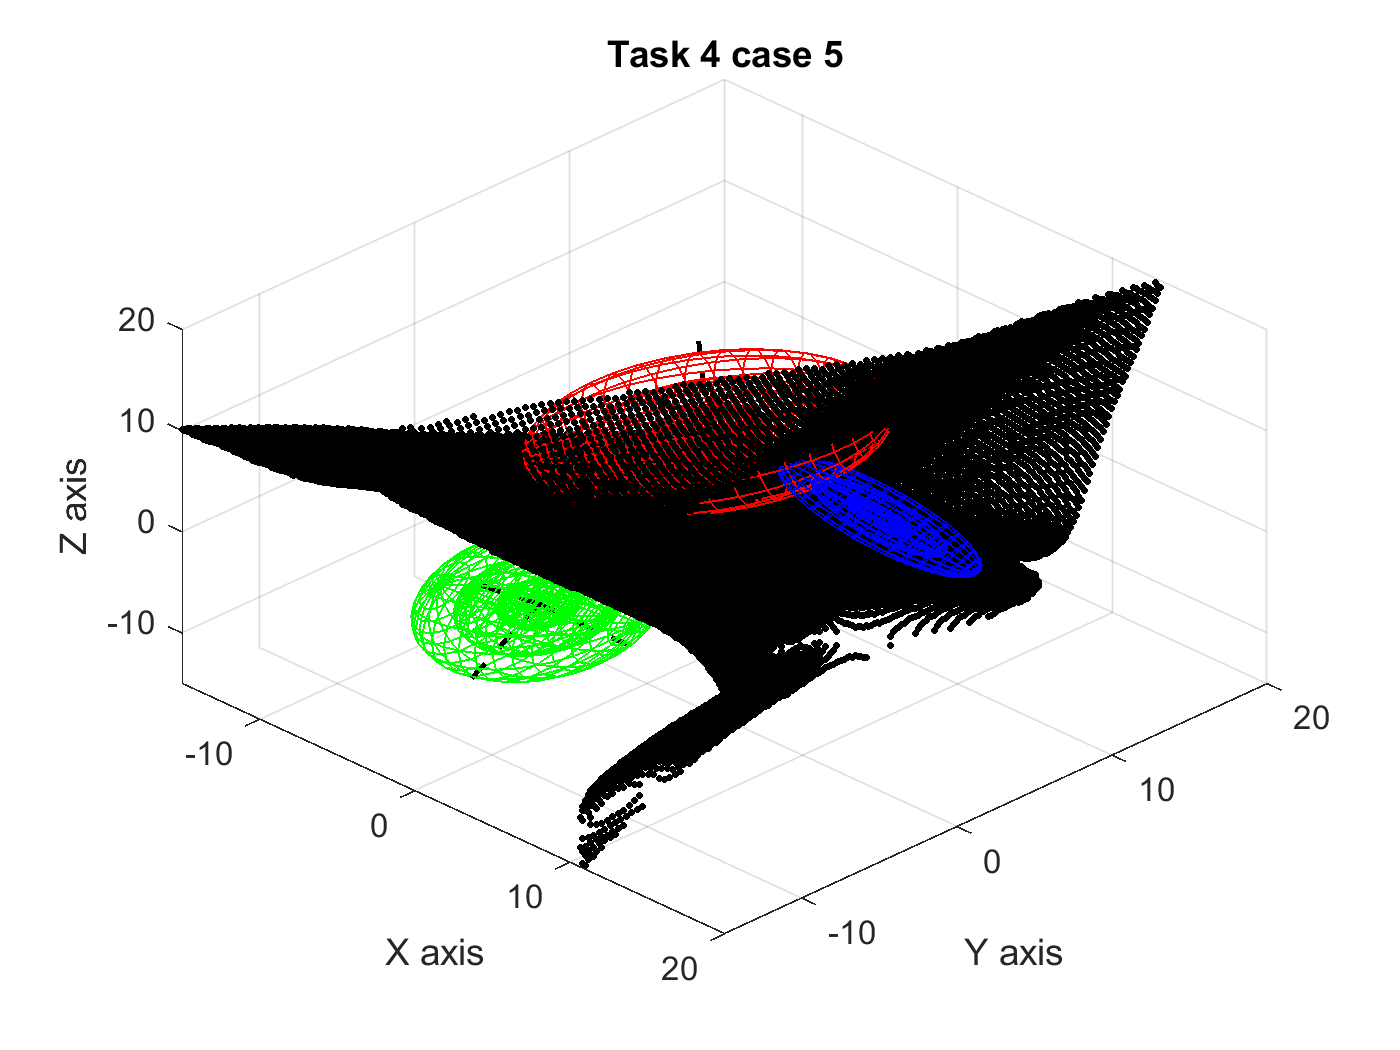

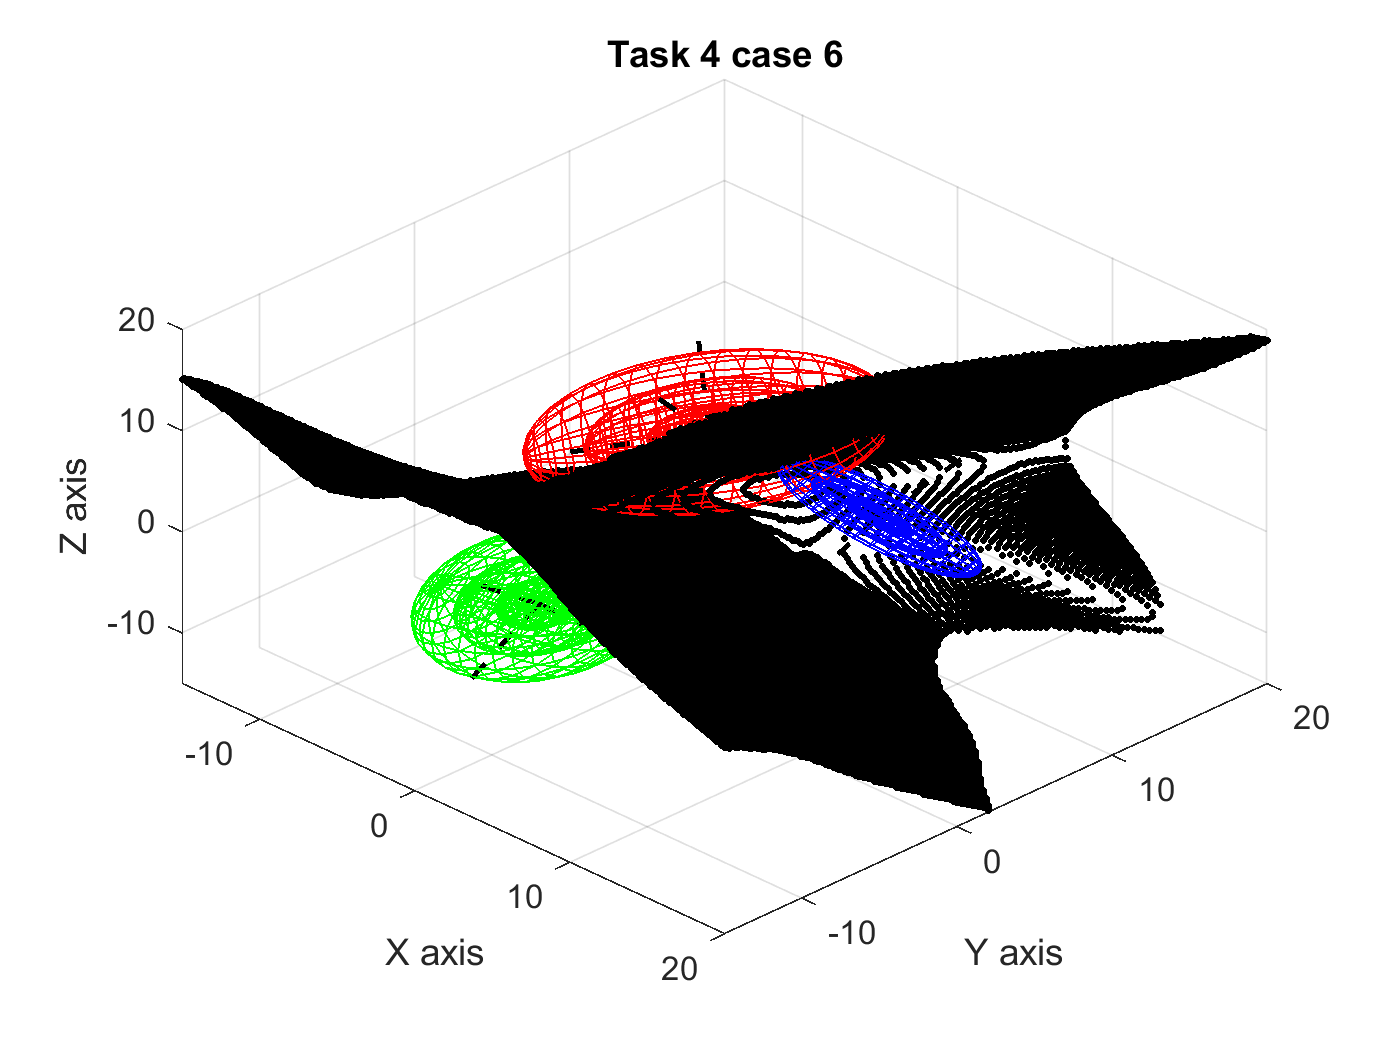

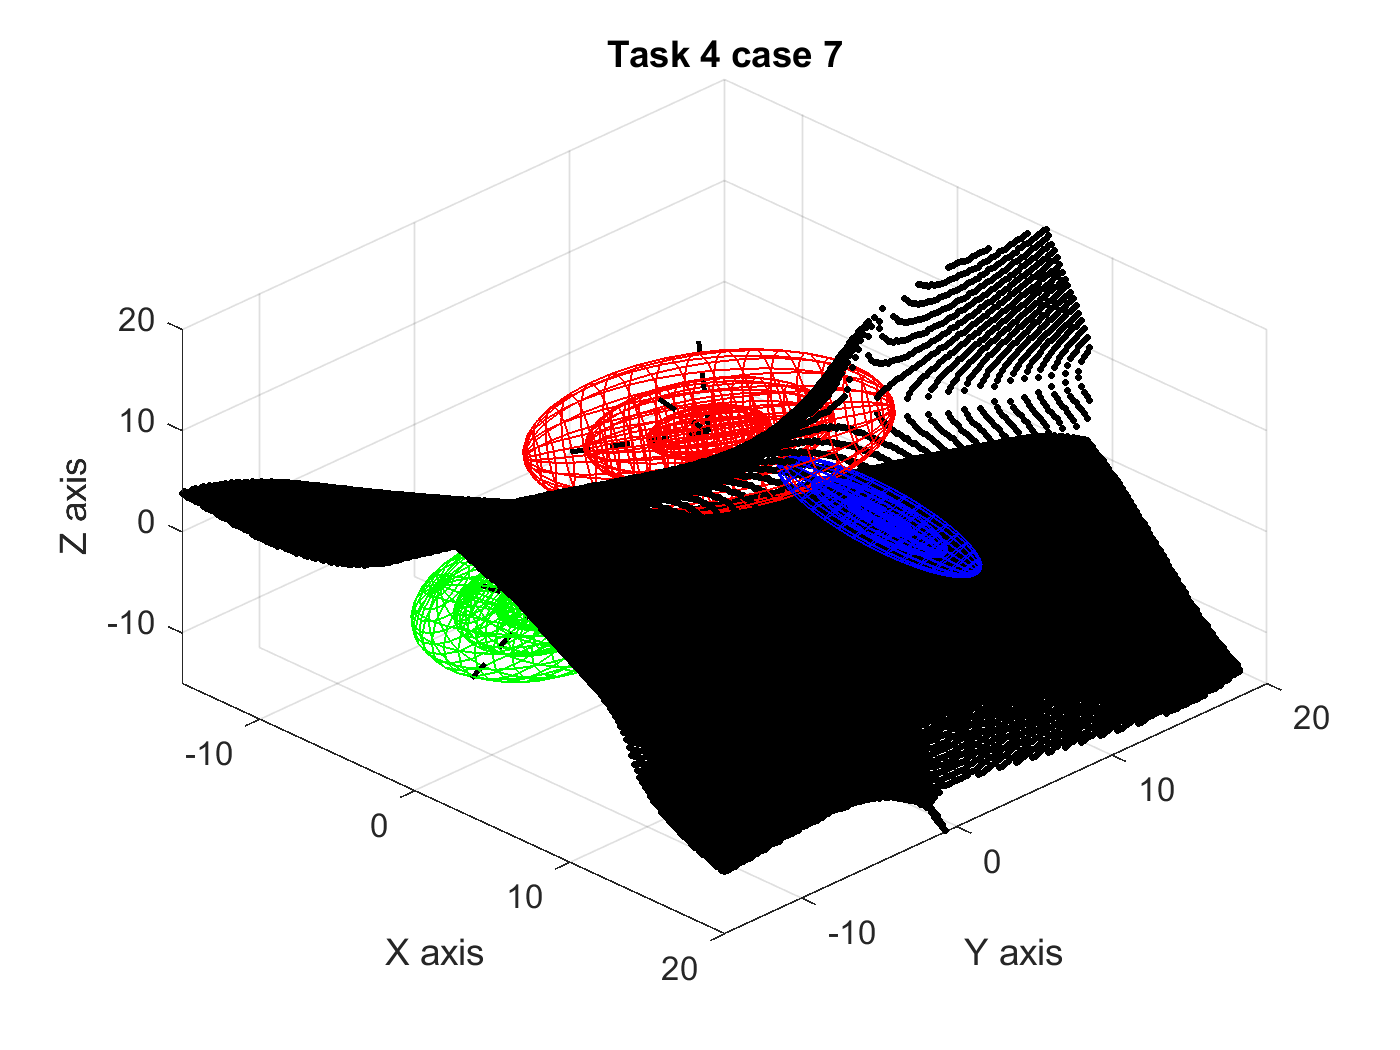

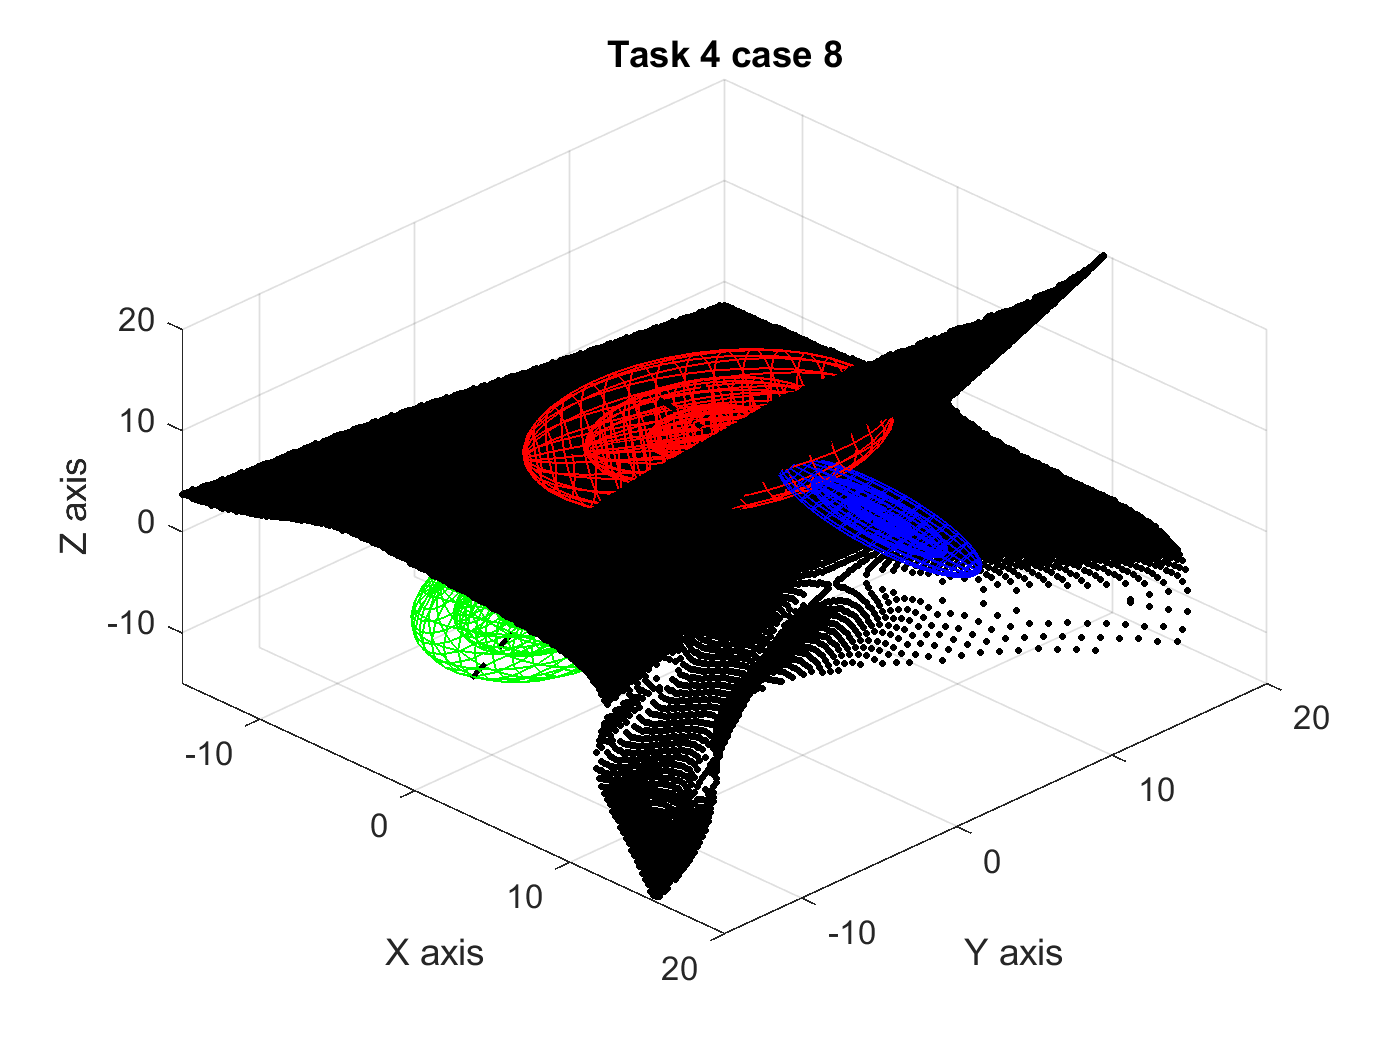

for i = 1:10
    s = i;
    figure(2+i)
    [class_index,~,~] = nn__classifier(data,targets,V,train_test_split,hidden_layer,s);
    b = decision_boundary(V,Npt,class_index);
    visualize_boundary(data_A, data_B, data_C, b);
    title(sprintf('Task 4 case %d',i))
end

**Discuss what would occur relative to the produced decision boundaries if 100 different neural network training were conducted.**

Training the neural network multiple times will generate different results each time due to different randomized initial conditions and sampling. Therefore, 100 different neural network training's will not have any positive impact on the produced decision boundary.

**Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary.**

The difference between the decision boundaries generated in the test cases above is the random seed used to initialize the classifier. Therefore, the case of which decision boundary is more correct is ultimatley dependant on chance. However, under these circumstances, we can state that whichever resulting decision boundary is most similar to the bayes decision boundary generated for the same three classes would be the most "correct". 

**Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s). **

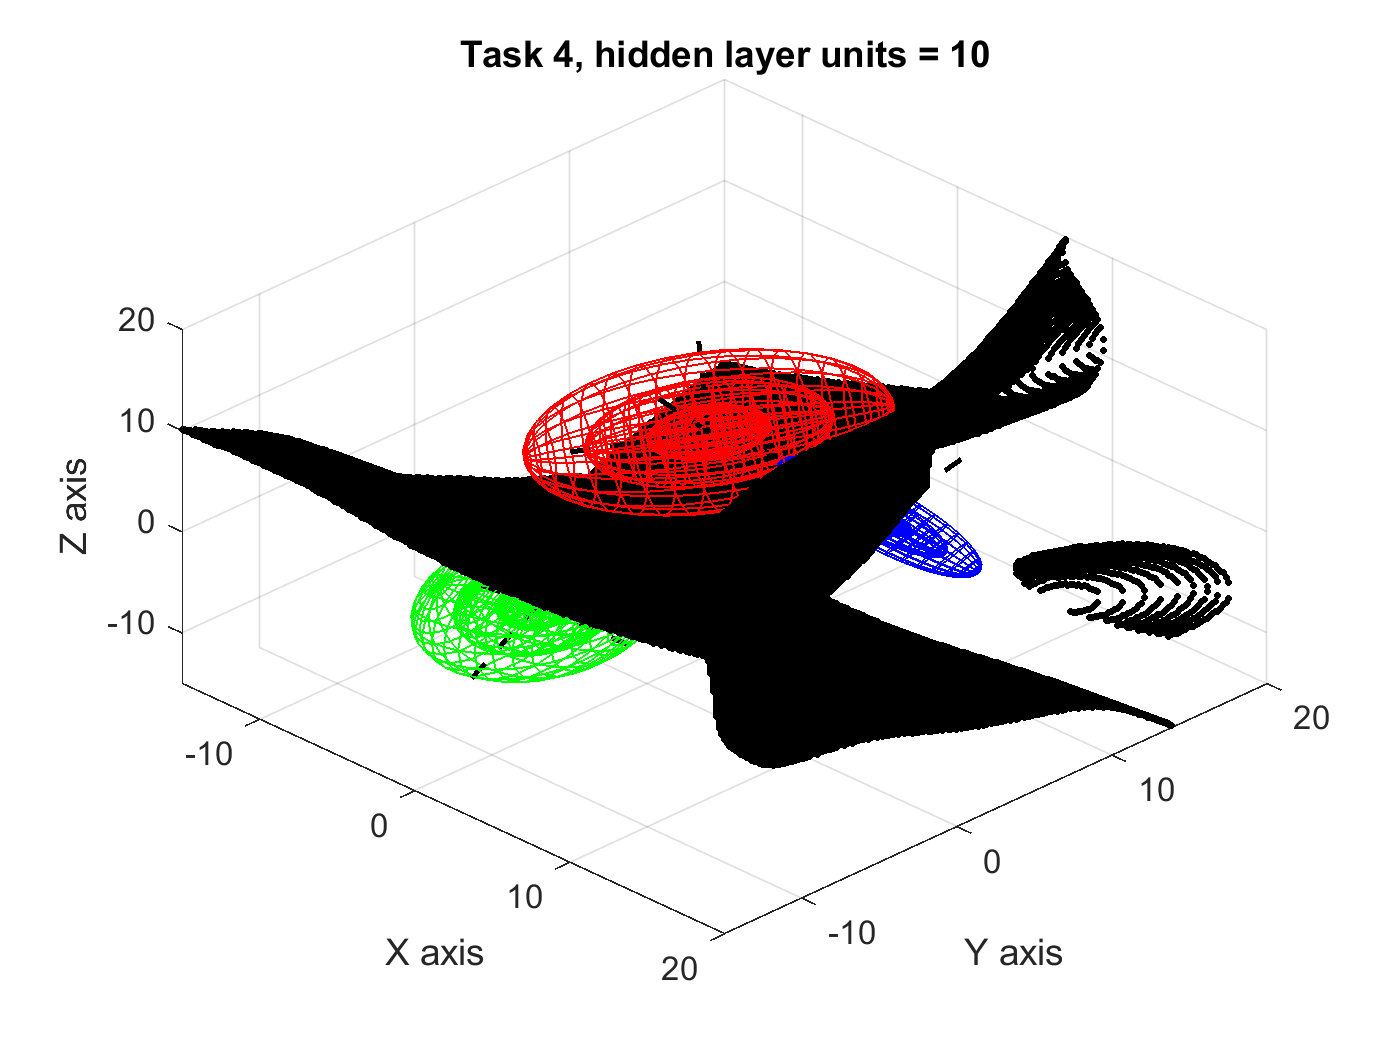

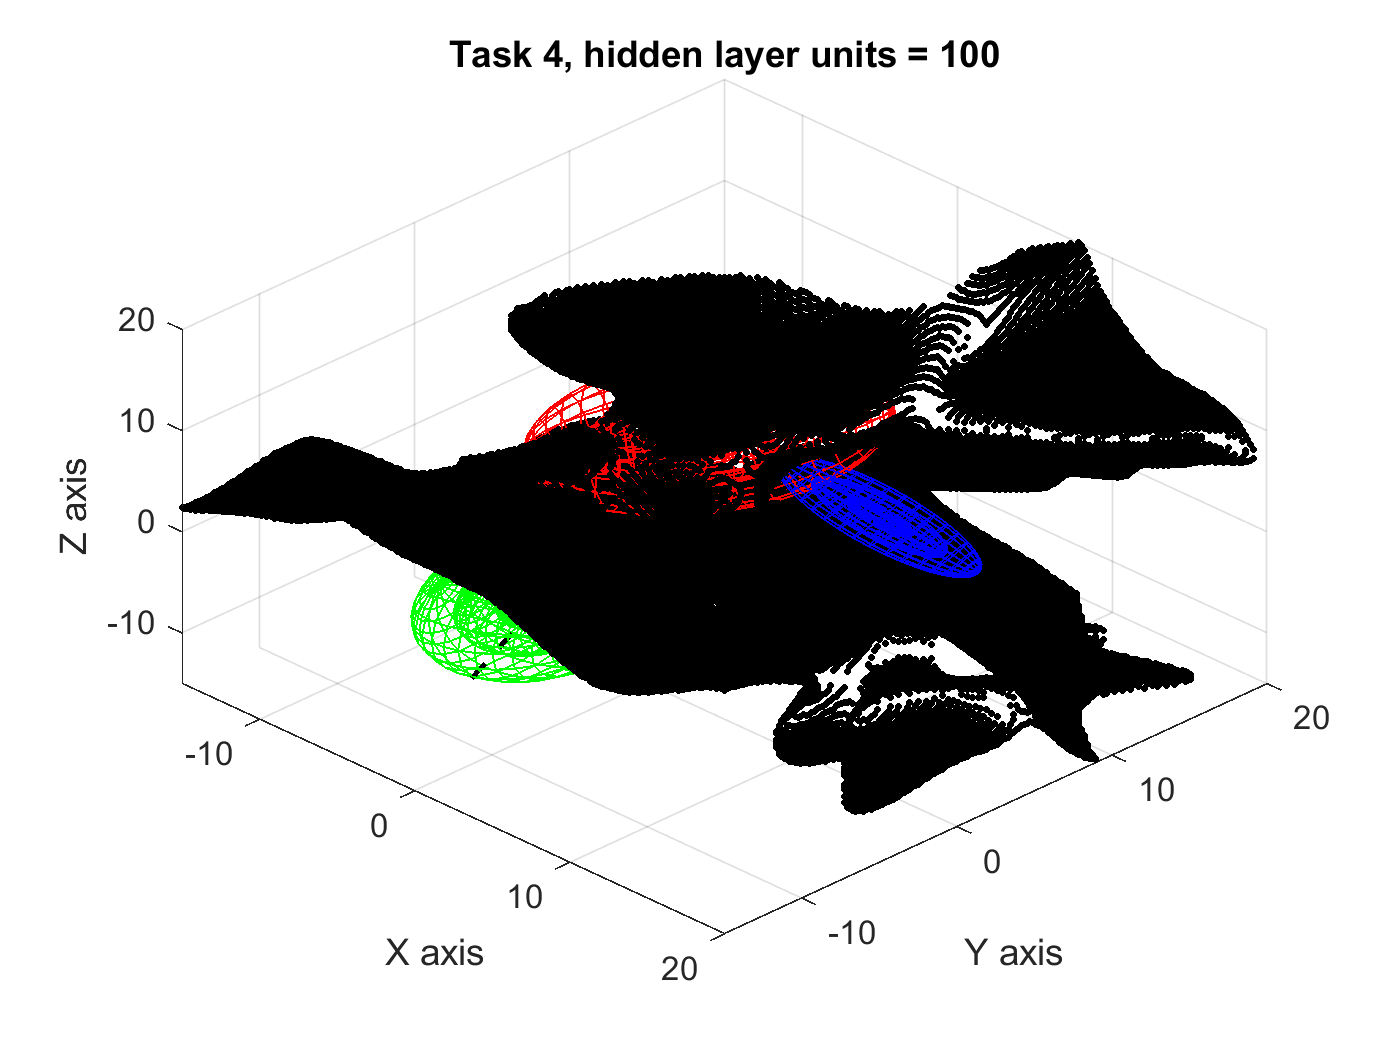

for i = 1:2
    s = 10;
    figure(12+i)
    hidden_layer_1 = 10^i;
    [class_index,~,~] = nn__classifier(data,targets,V,train_test_split,hidden_layer_1,s);
    b = decision_boundary(V,Npt,class_index);
    visualize_boundary(data_A, data_B, data_C, b);
    title(sprintf('Task 4, hidden layer units = %d',hidden_layer_1 ))
end

The number of neurons, or hidden units, between layers governs the expressive power of the net and consequentially the complexity of the descision boundary. For classes that are well seperated or linearly seperable few hidden units are required, and as the complexity of the classes and their interconnection increases so does the need for hidden units. Therefore, as we incerase the number of hidden units we would expect to see an improvement in the decision boundaries generated by the neural network. It is worth noting, that for practical application, passed a certain threshold (which depends on the complexity of the data at hand) the addition of more hidden units will cause the decision boundaries to overfit (as in hidden layer units = 100) to the training data resulting in low generlizability and high rates of testing error.

**Task 5: **Discuss in detail why or why not the neural network will ever be able to produce decision boundaries equivalent to the Bayes boundaries.

Solution:

The bayes decision boundary provides the optimal solution to the general decision problem due to the known probability structure underlying the categories. However the application of Bayes theory, requires estimated conditional PDFs which become harder when dimensionality of the feature space assumes relatively large values. In this scenario working with neural networks will be prefer. The neural network will be able to performan close to the Bayes optimal classifier but can never match its performance. This is because the Bayesian classifier exploits the statistical information for the data distribution while the neural network does not take into account such information.  Neural network try to optimize the classification by trying to minimize the respective empirical loss. The form of non-linearity is learned from the training data.

**Task 6** - Assess whether or not the neural network boundaries are more or less sensitive to outliers than the Bayesian boundaries.

Solution:

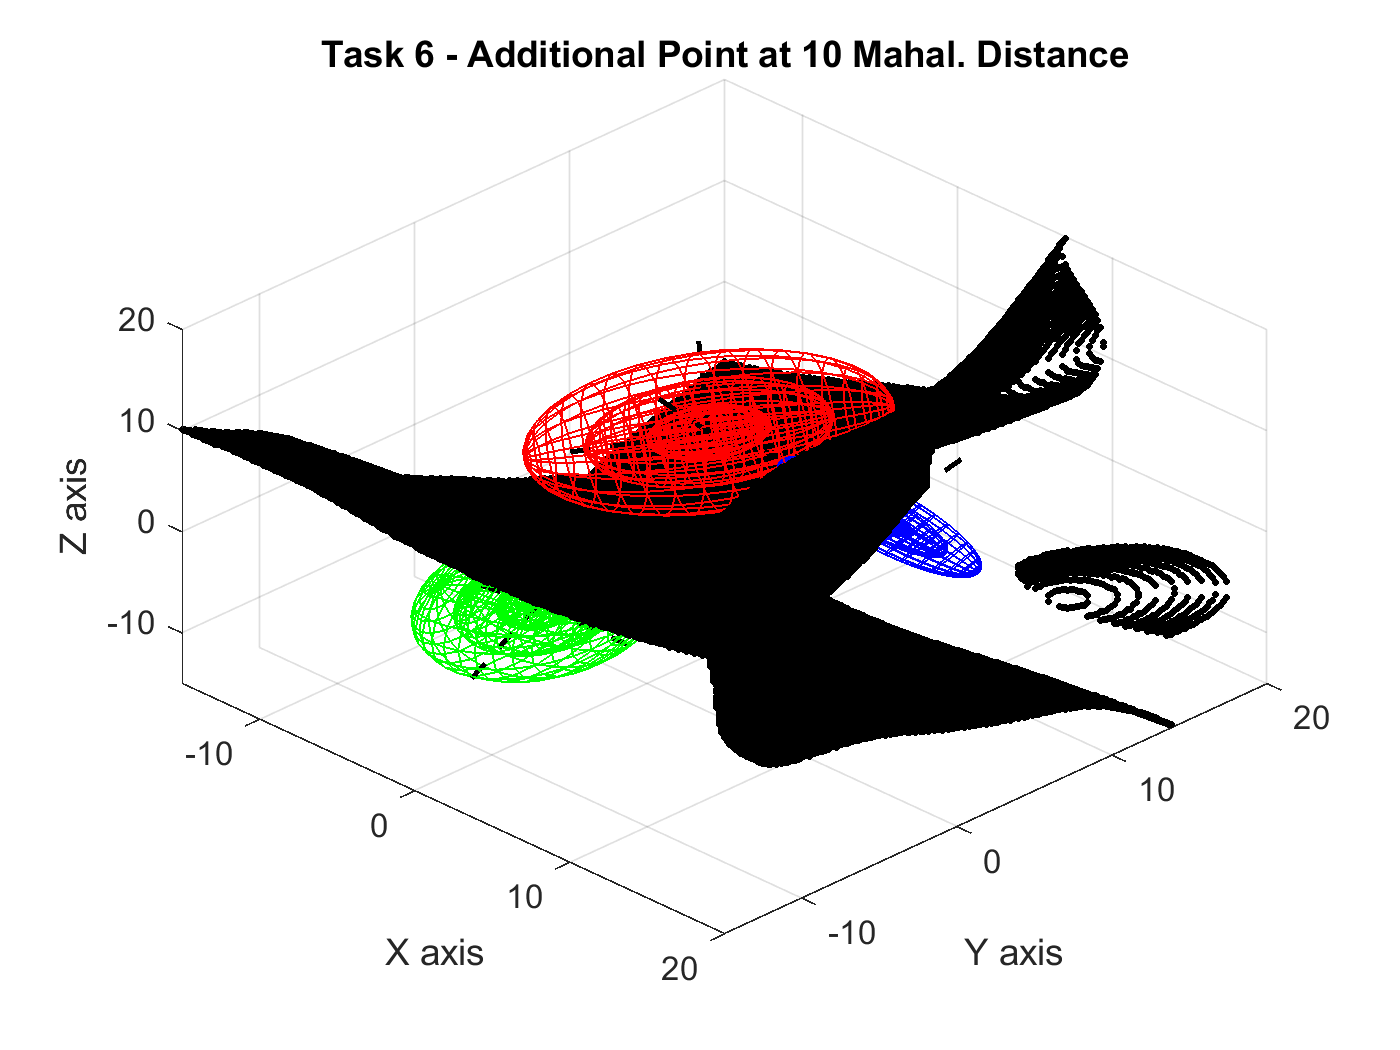

target_T6 = [1*ones(K,1); 2*ones(K+1,1); 3*ones(K,1)];
s = 10;
figure(15)
pt_mal_10 = additional_pts(mu_B, sigma_B, 10)'; % Finding a point at the desired mahalanobis distance 
data_B_p10 = [data_B;pt_mal_10]; % Adding the new point to the original dataset A 
data_p10 = [data_A; data_B_p10; data_C];
[class_index,~,~] = nn__classifier(data_p10,target_T6,V,train_test_split,hidden_layer,s);
b = decision_boundary(V,Npt,class_index);
visualize_boundary(data_A, data_B_p10, data_C, b);
title('Task 6 - Additional Point at 10 Mahal. Distance')

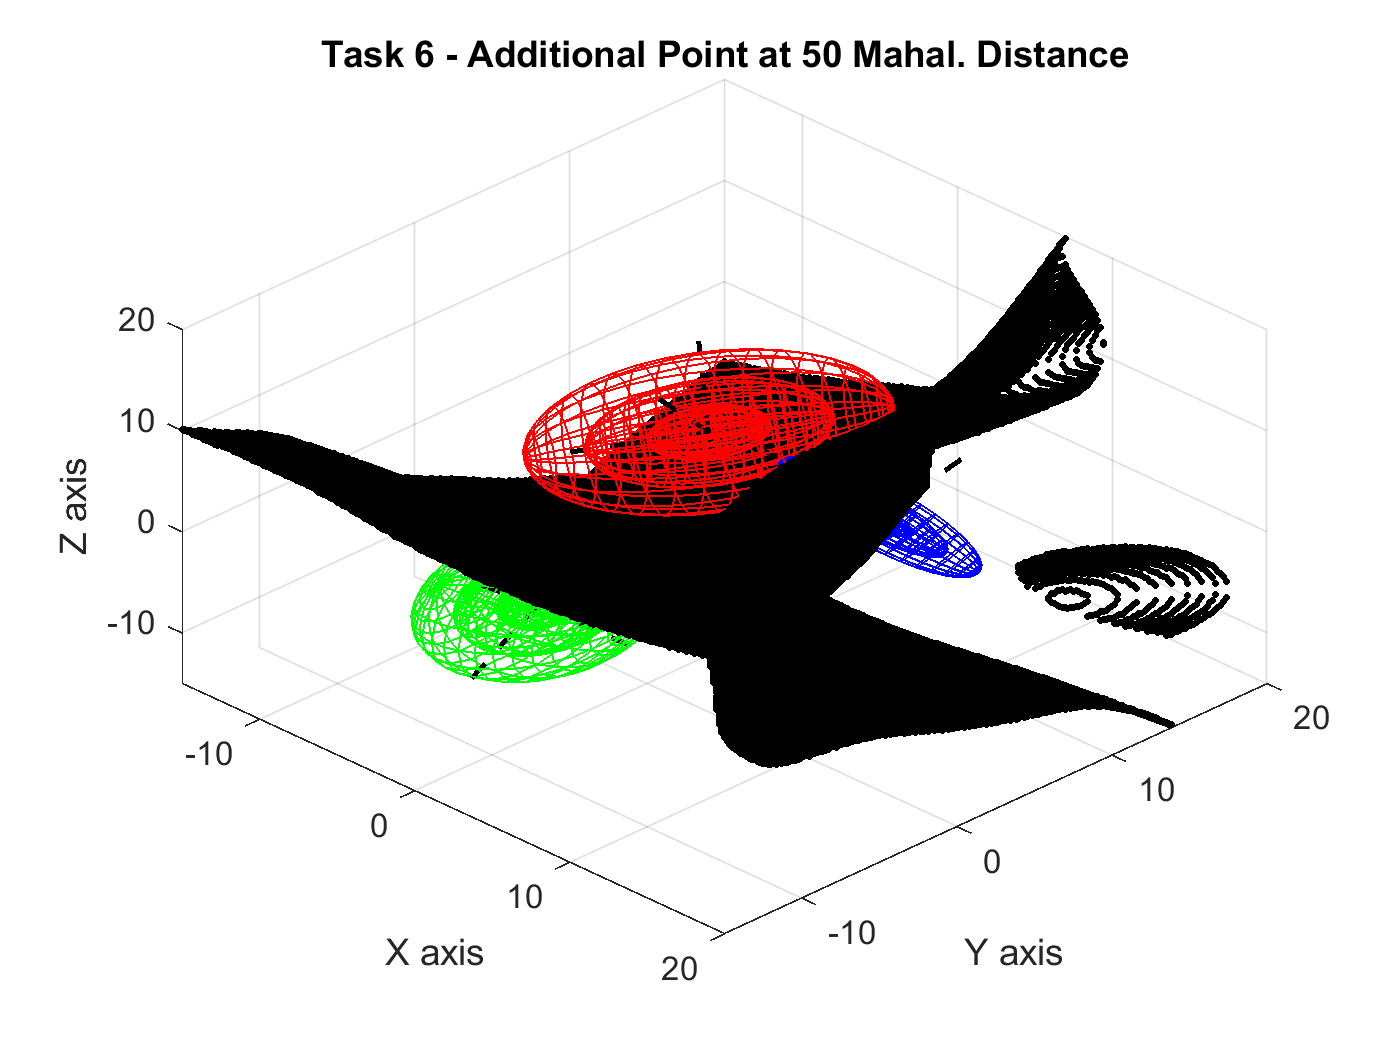


figure(16)
pt_mal_50 = additional_pts(mu_B, sigma_B, 50)'; % Finding a point at the desired mahalanobis distance 
data_B_p50 = [data_B;pt_mal_50]; % Adding the new point to the original dataset A 
data_p50 = [data_A; data_B_p50; data_C];
[class_index,~,~] = nn__classifier(data_p50,target_T6,V,train_test_split,hidden_layer,s);
b = decision_boundary(V,Npt,class_index);
visualize_boundary(data_A, data_B_p50, data_C, b);
title('Task 6 - Additional Point at 50 Mahal. Distance')

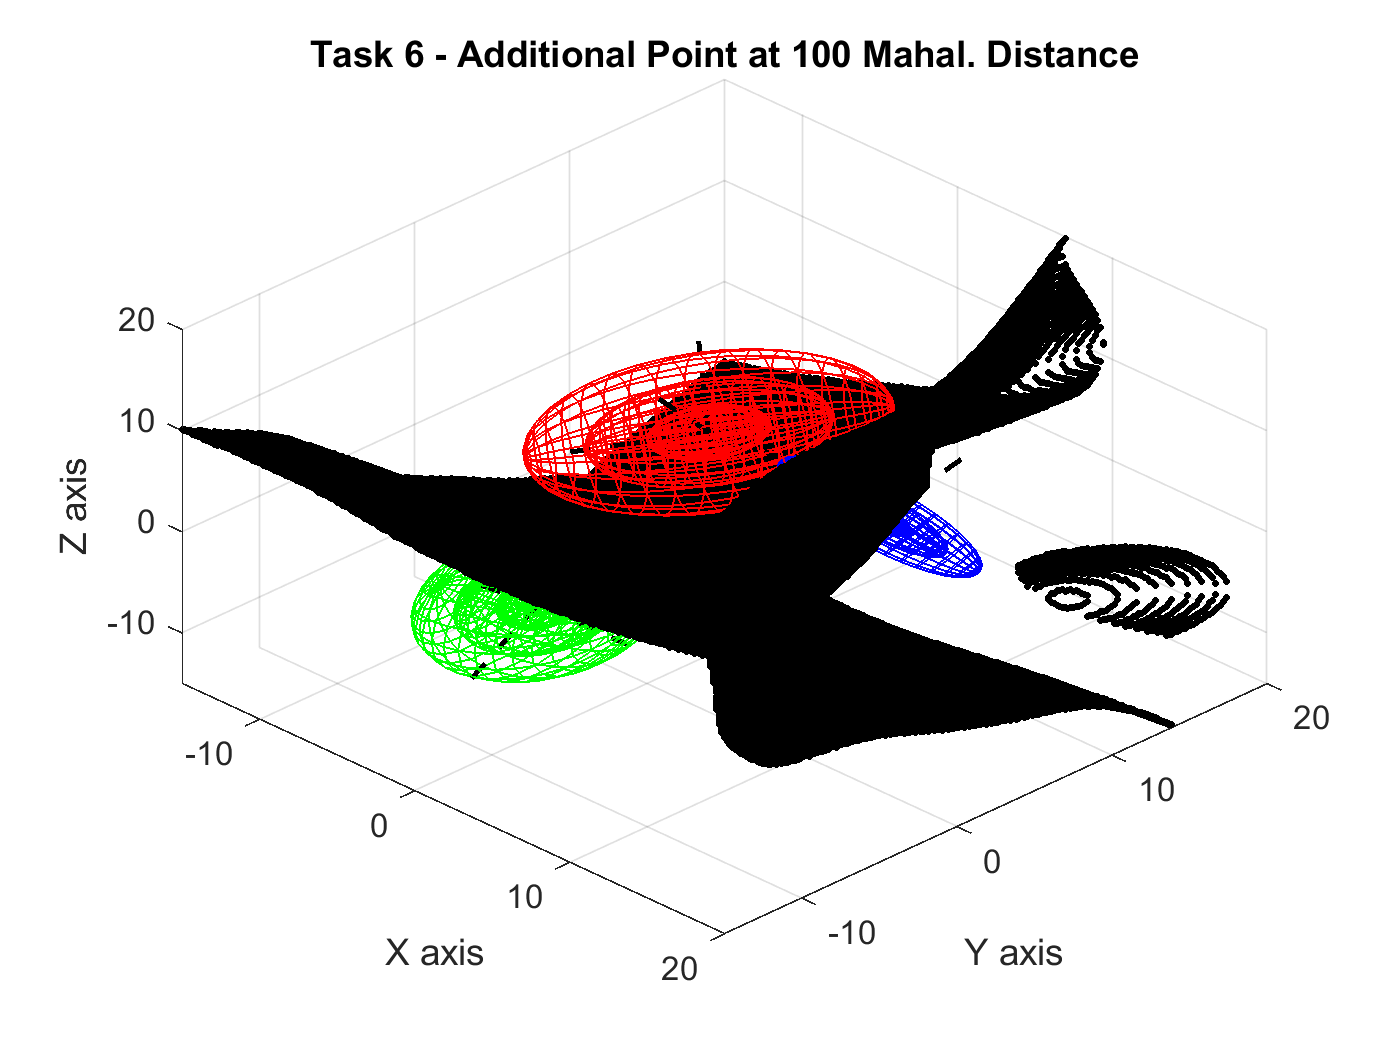


figure(17)
pt_mal_100 = additional_pts(mu_B, sigma_B, 100)'; % Finding a point at the desired mahalanobis distance 
data_B_p100 = [data_B;pt_mal_100]; % Adding the new point to the original dataset A 
data_p100 = [data_A; data_B_p100; data_C];
[class_index,~,~] = nn__classifier(data_p50,target_T6,V,train_test_split,hidden_layer,s);
b = decision_boundary(V,Npt,class_index);
visualize_boundary(data_A, data_B_p100, data_C, b);
title('Task 6 - Additional Point at 100 Mahal. Distance')

**Comments: **

From above plots it can be seen that neural networks are much more robust to outliers than the Bayes classifier. There are slight changes in boundary and variations are far less than what was observed in bayes classifier. This makes sense since the boundaries here generated by a neural network are based on labeled data rather than summary statistics of the given classes (as they are for bayesian classification) which can be heavily impacted by a single point.

**Task 7**: Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.

Solution:

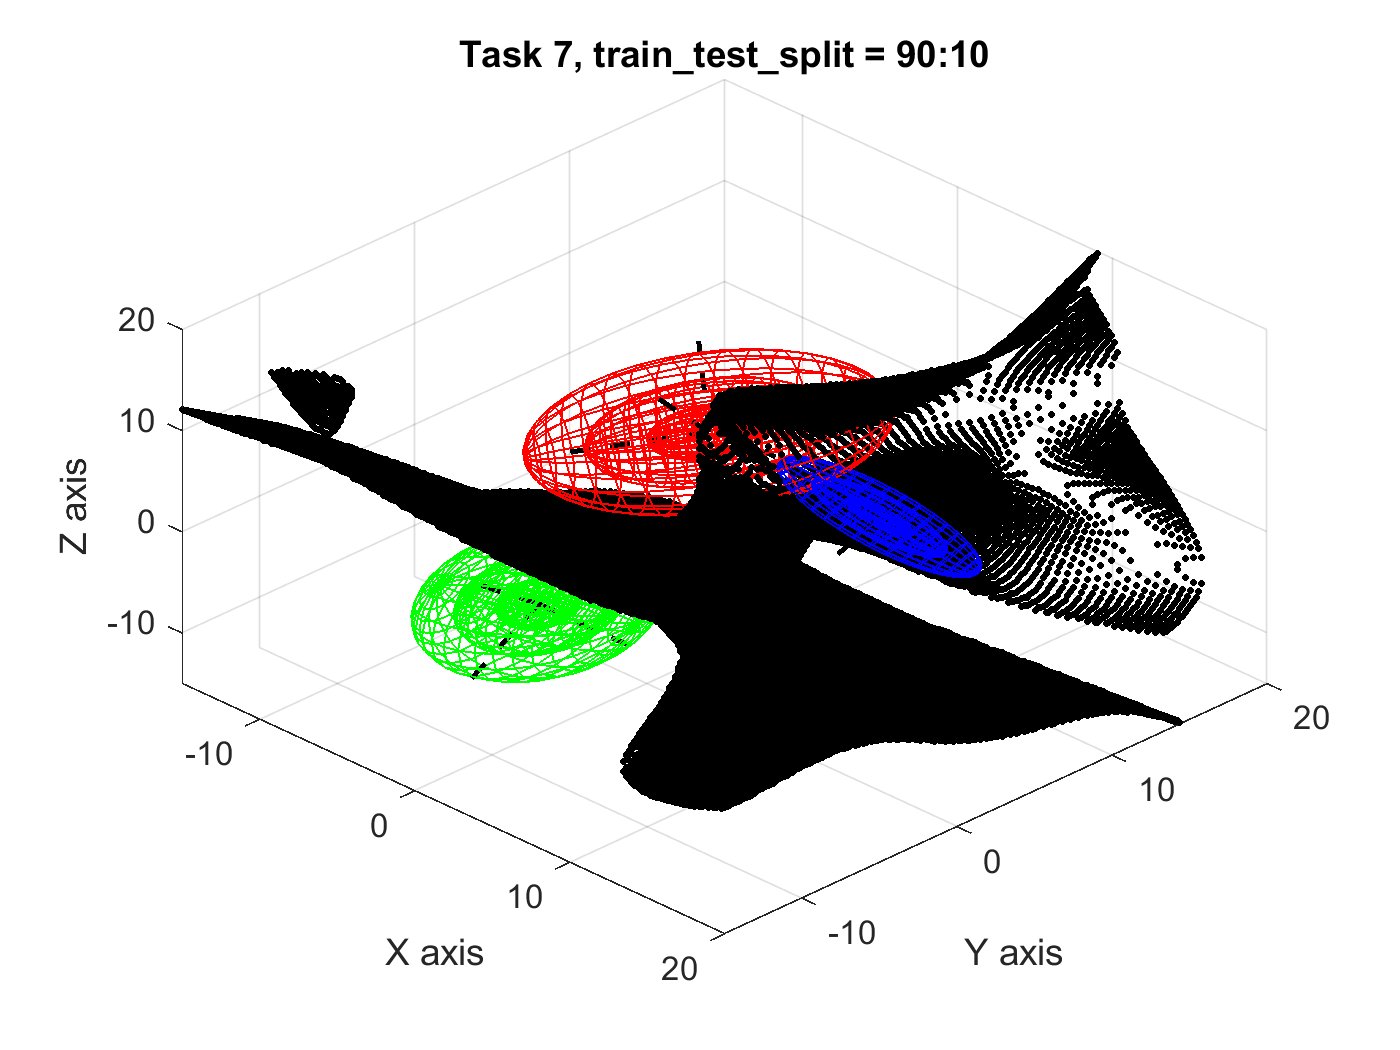

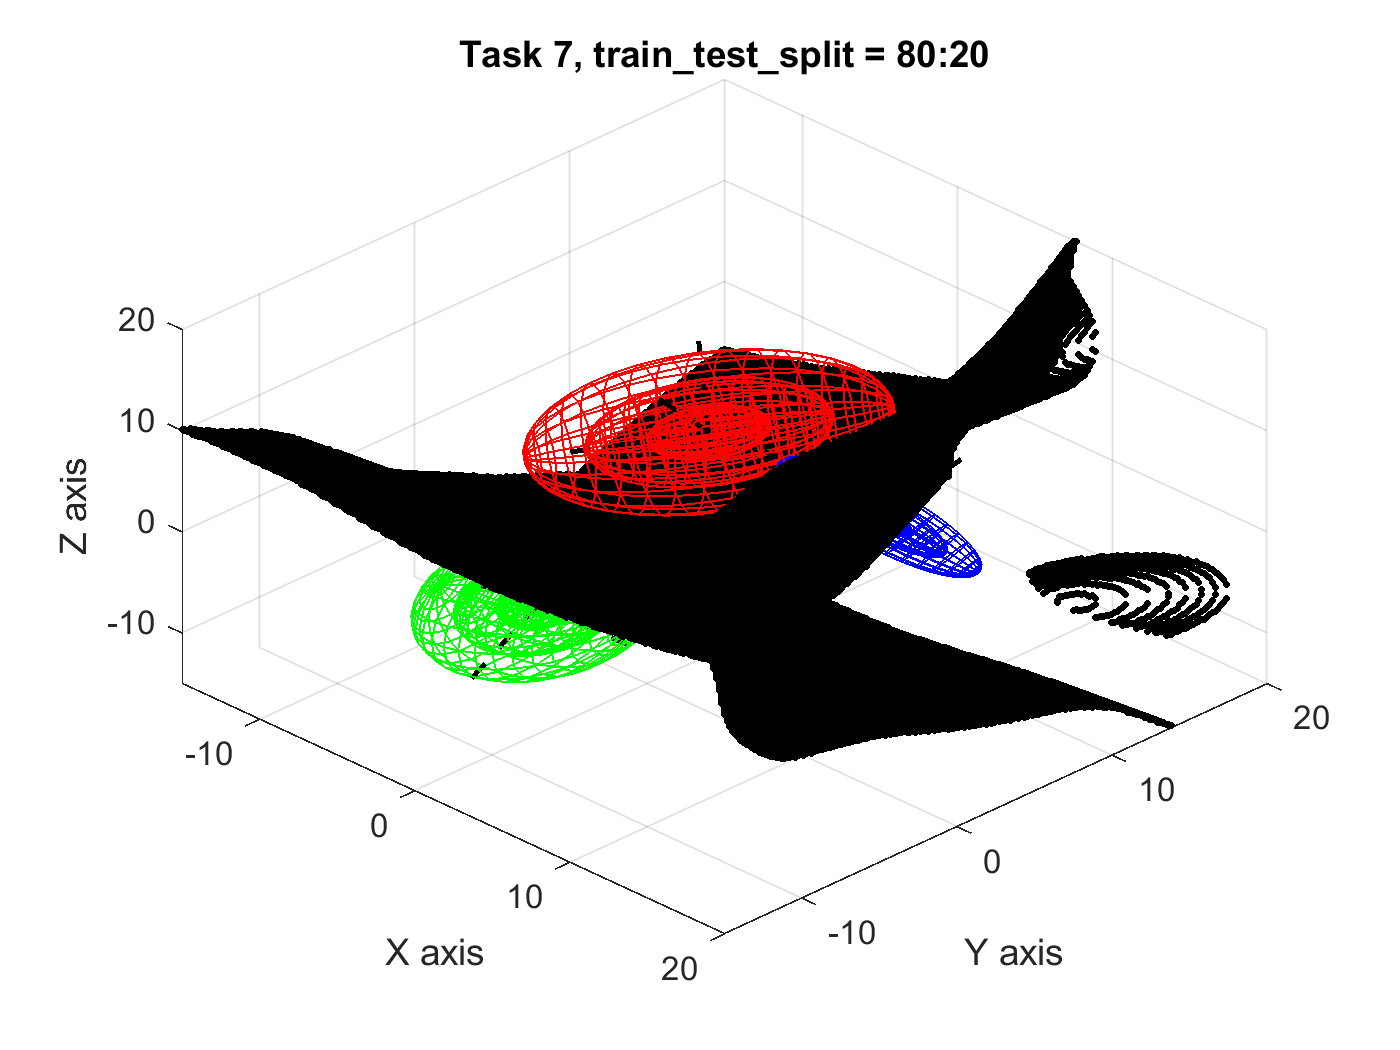

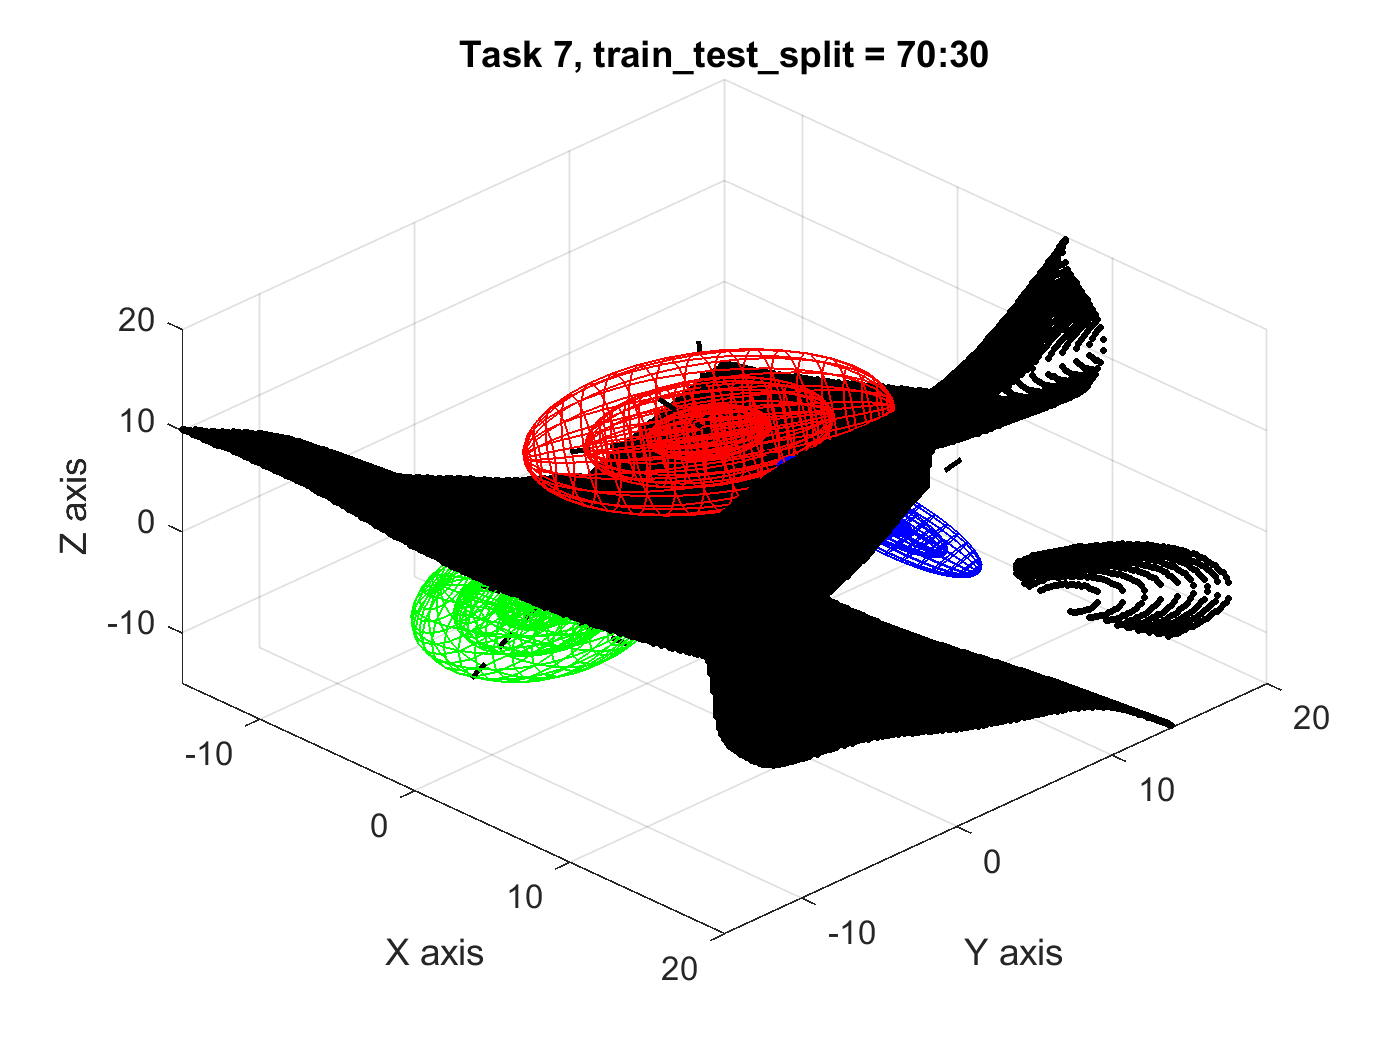

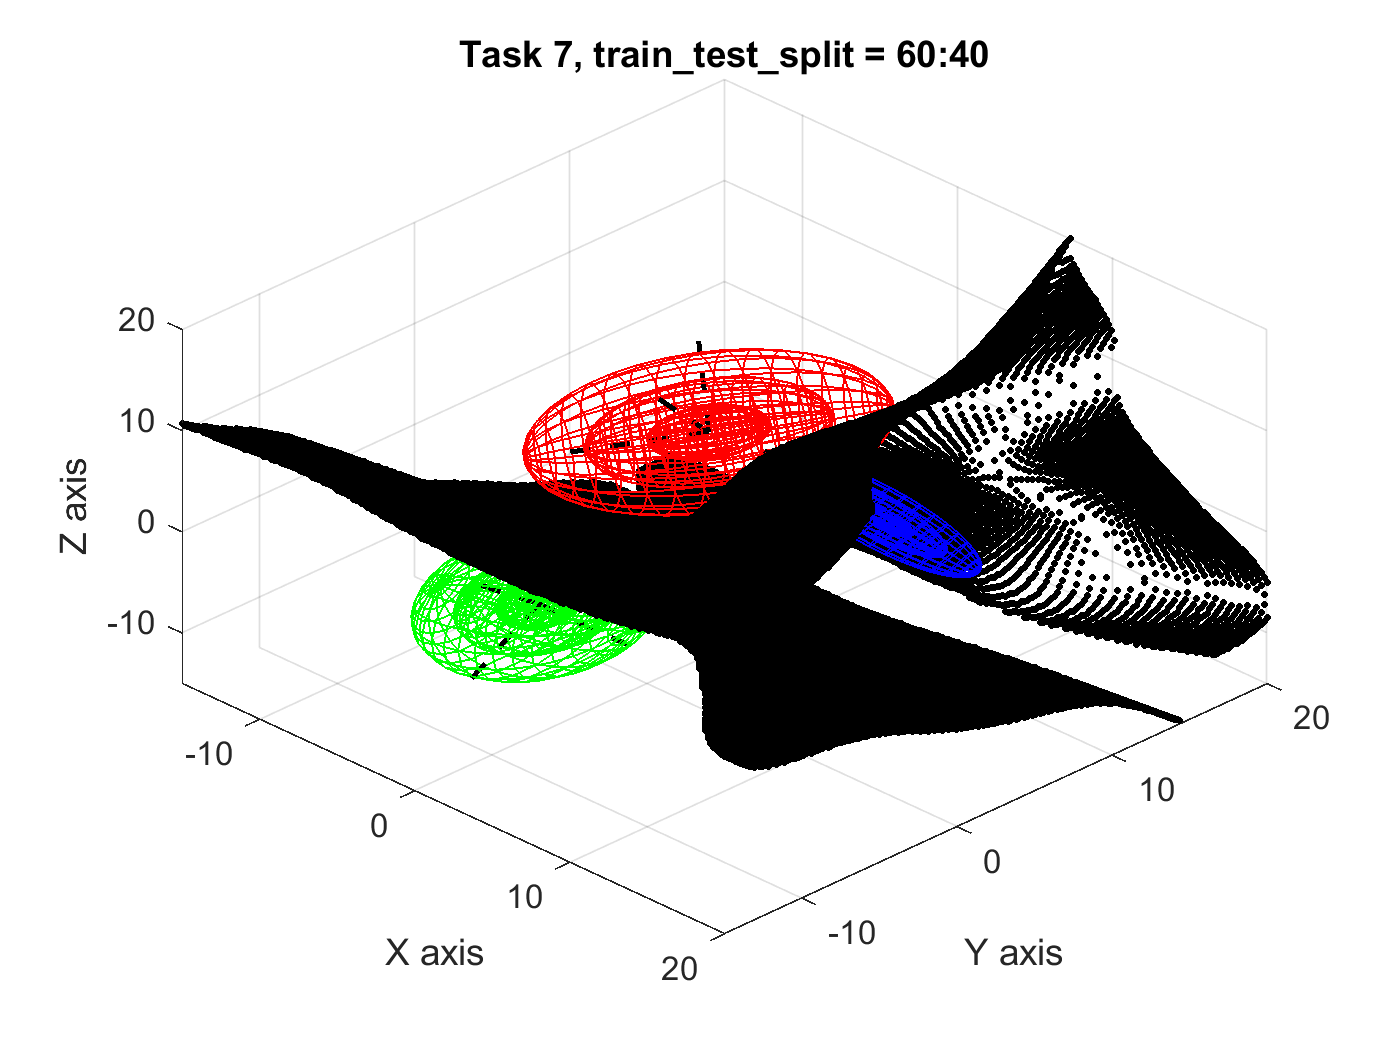

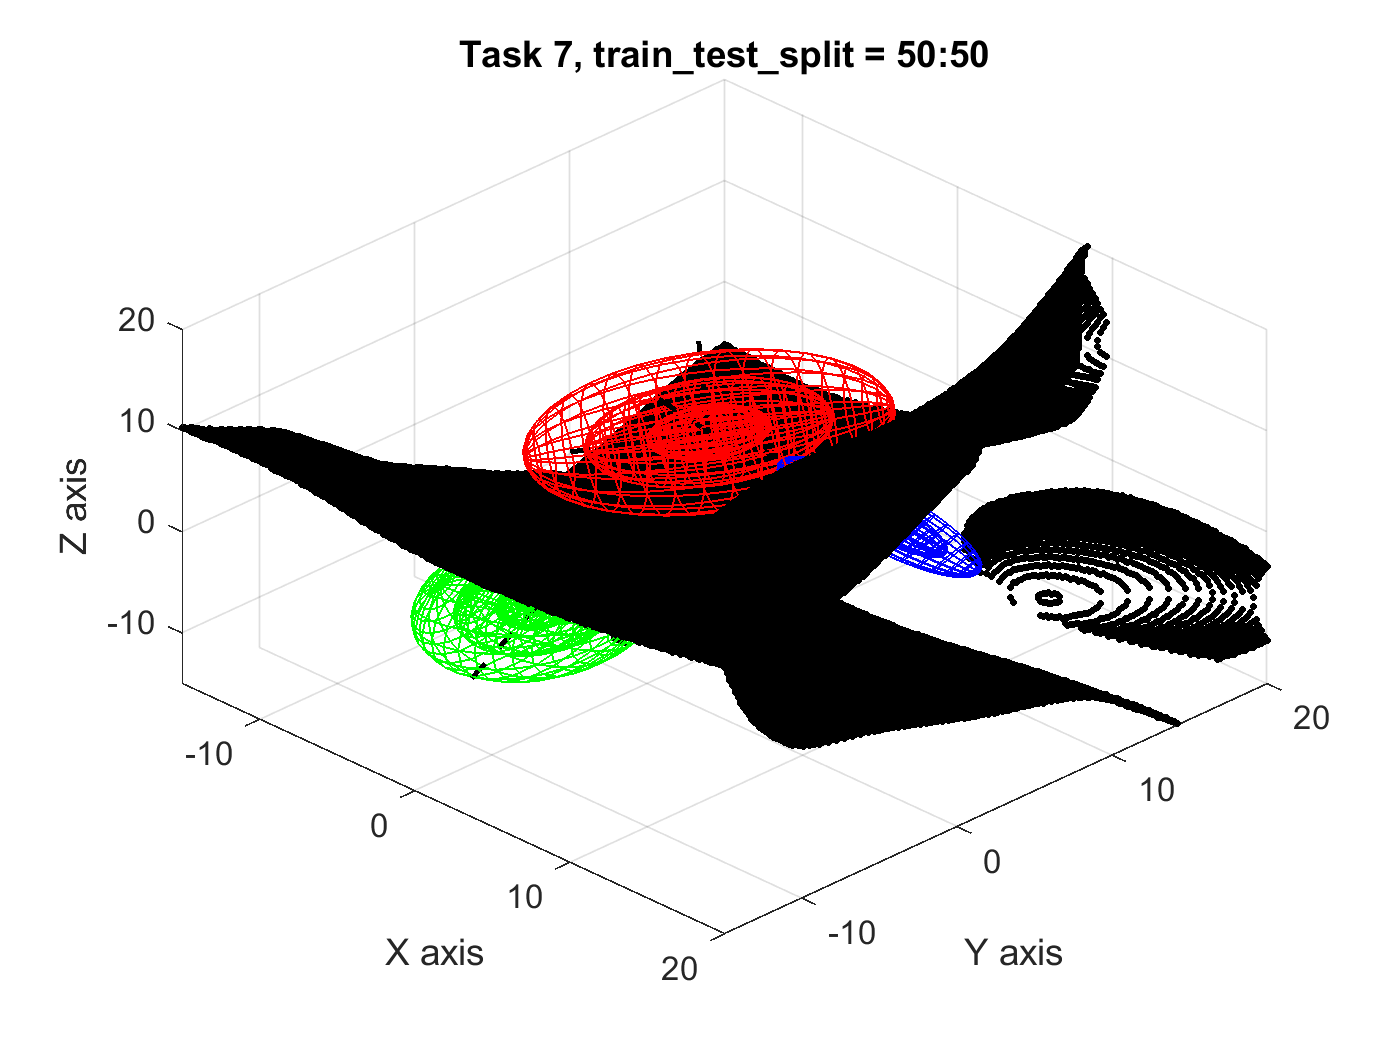

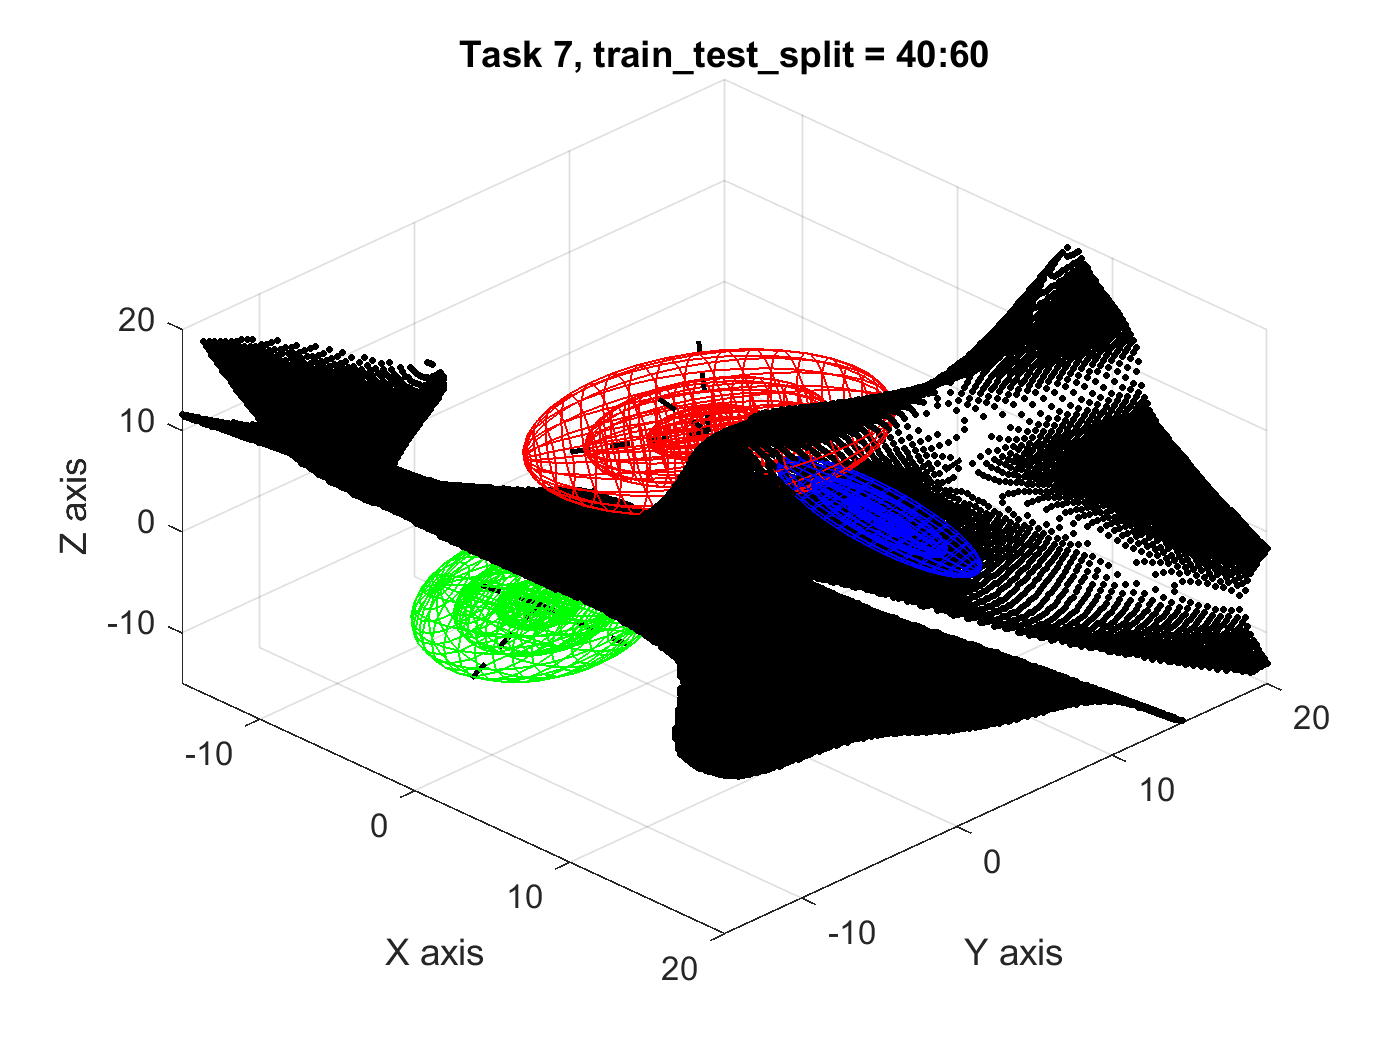

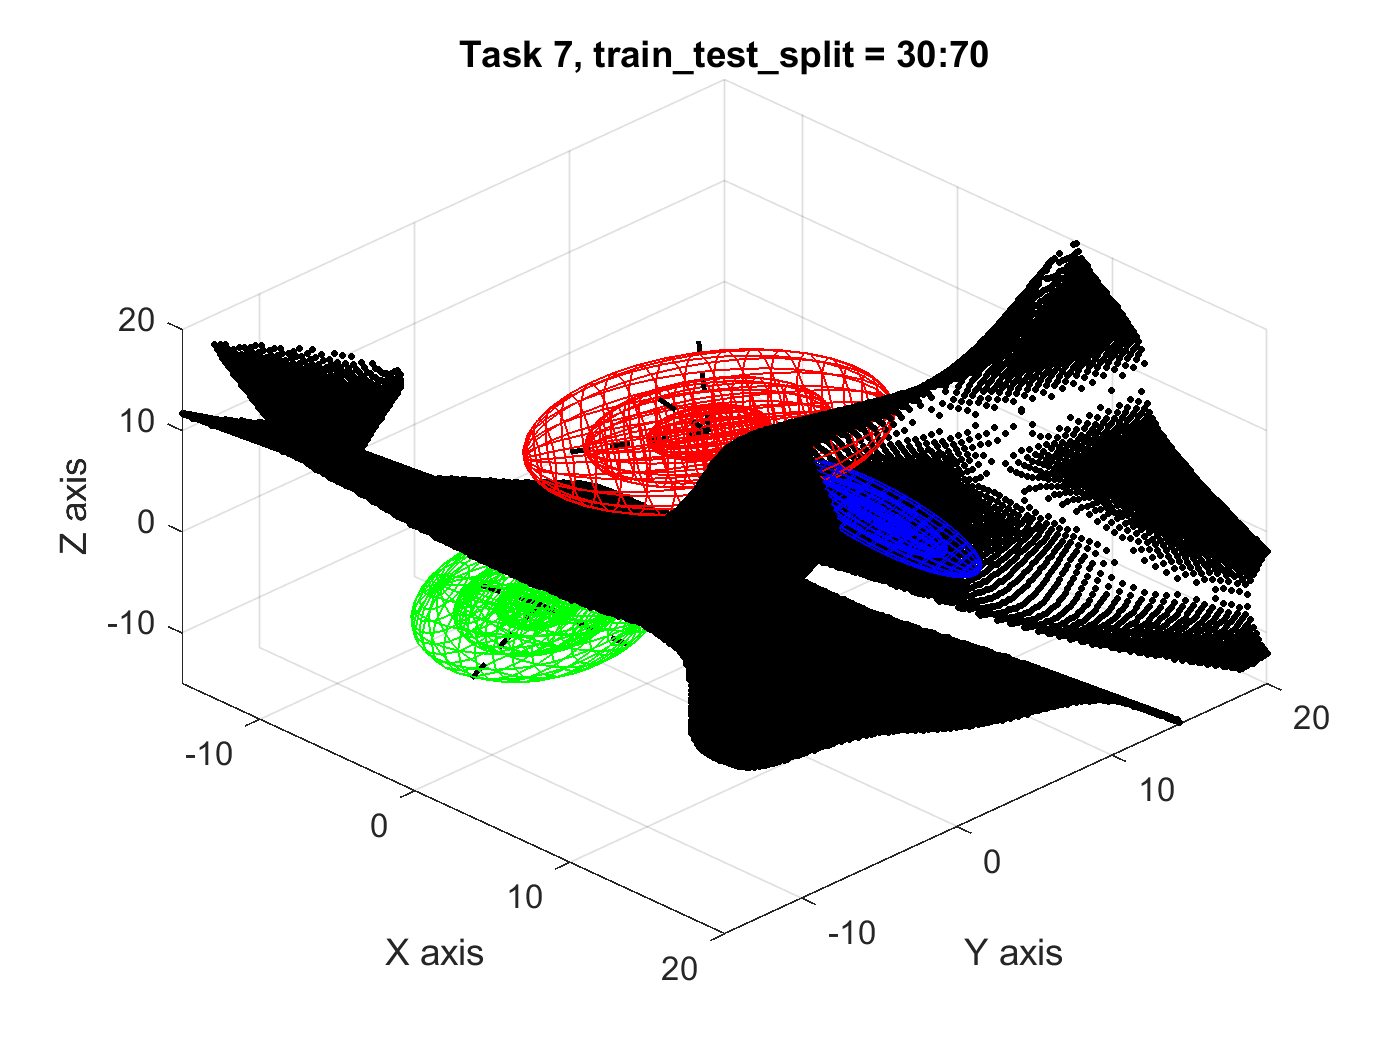

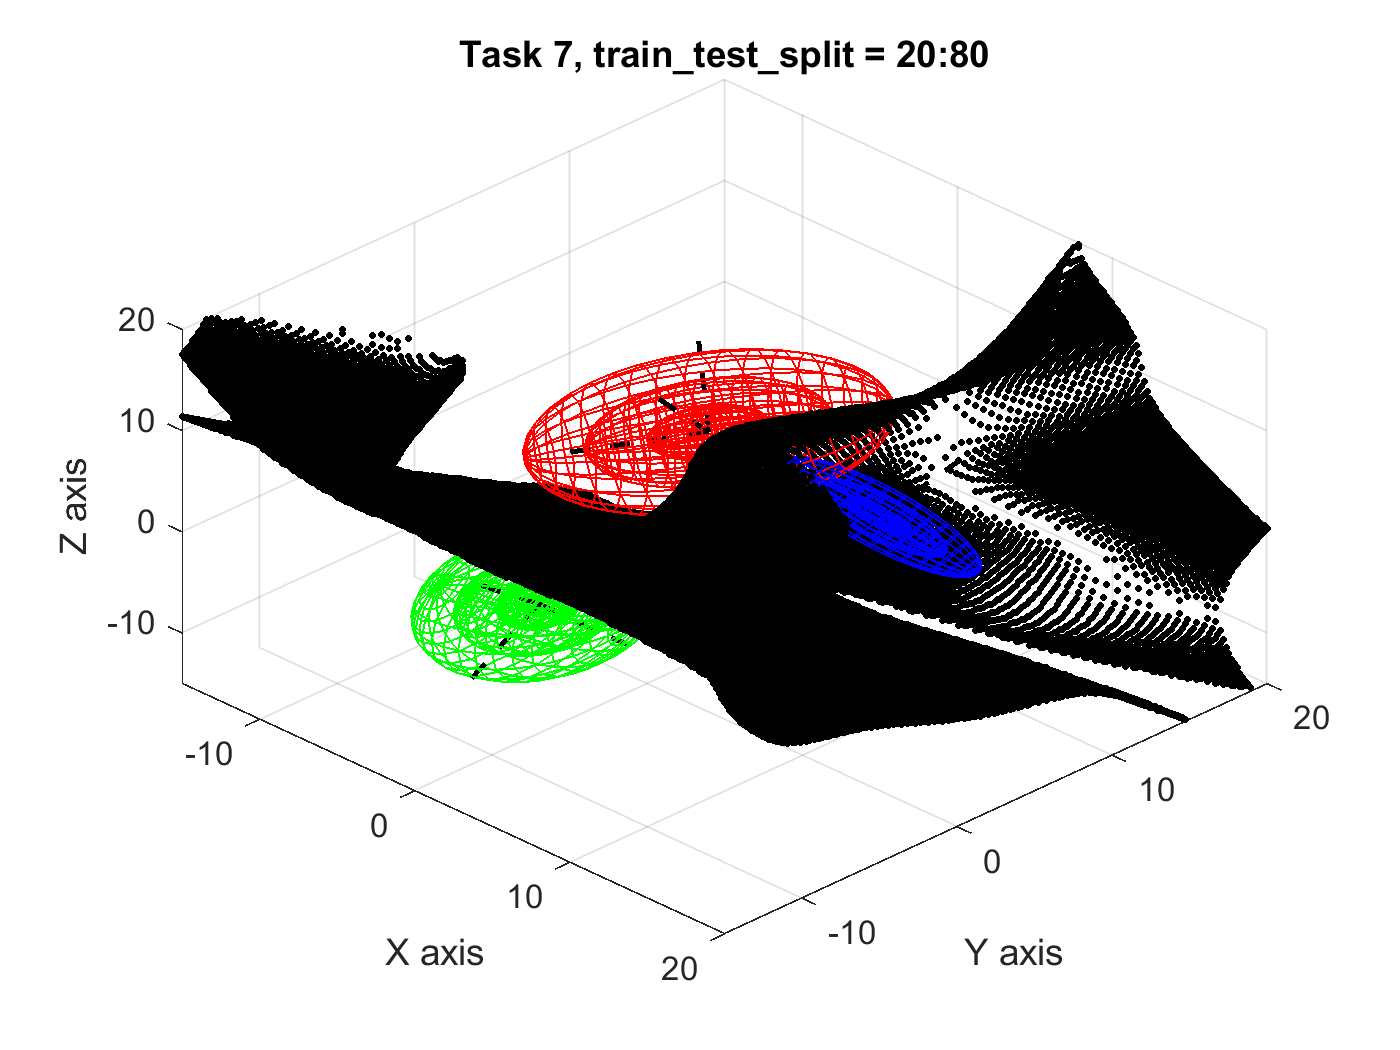

for i = 1:9
    s = 10;
    figure(17+i)
    train_test_split = 1-0.1*i;
    
    [class_index,~,~] = nn__classifier(data,targets,V,train_test_split,hidden_layer,s);
    b = decision_boundary(V,Npt,class_index);
    visualize_boundary(data_A, data_B, data_C, b);
    title(sprintf('Task 7, train\\_test\\_split = %d:%d',round(train_test_split*100),round((1-train_test_split)*100) ))
end

Generalization is often interpreted as the broad ability of a classifier to handle new scenarios while overfitting is used to describe any unwanted performance drop of a machine learning model . Having more training data helps generalization i.e. for any particular test example, the larger the training set, the more likely there will be a closely related training example. Larger training set, will account for more variance in data and result in few accidental regularities, so the network will be forced to pick up the true regularities. Therefore, generalization error ought to improve as we add more training examples. On the other hand, small training sets are easier to memorize than large ones, so training error tends to increase as we add more examples. As the training set gets larger, the two will eventually meet.

function f = gaussian_data(K,D,mu,sigma)
%function for generating gaussian data
    % generate a subset of samples from normal distribution
    N = randn(K,D);
    % centralize the data at zero-mean
    N_c = N - mean(N);
    % obtain eigen values and eigen vectors for covariance of N
    [v,d] = eig(cov(N_c));
    %generate the whitening transform
    R = v*inv(sqrt(d));
    %apply the whitening transform on the centralized data
    W  = N_c*R;
    %obtain eigen values and eigen vectors for sigma
    [vn,dn] = eig(sigma);
    % generate the inverse whitening transform
    R_inv = sqrt(dn)*inv(vn);
    % apply the inverse whitening transfrom on the whitened gaussian data
    f = W*R_inv;  
    % centralize the data at mu
    f = f + mu;
end 

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    

    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);

        
end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function [class_index,e,performance] = nn__classifier(data,targets,V,train_test_split,hidden_layer,s)
    rng(s);
%train_test_split gives the fraction of training data over the whole data

    target_new = bsxfun(@eq, targets(:), 1:max(targets)); %one hot encoder
    %neural network classifier
    %use nprtool to open the neural network pattern recognition app
    x = data';
    t = target_new';

    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems.
    % 'trainscg' uses less memory. Suitable in low memory situations.
    trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

    % Create a Pattern Recognition Network
    hiddenLayerSize = hidden_layer;
    net = patternnet(hiddenLayerSize, trainFcn);

    % % Setup Division of Data for Training, Validation, Testing
    net.divideParam.trainRatio = train_test_split;
    net.divideParam.valRatio = (1-train_test_split)/2;
    net.divideParam.testRatio = (1-train_test_split)/2;

    %decide if you want to show the pop-up window 
    net.trainParam.showWindow = 0;

    % Train the Network
    [net,tr] = train(net,x,t);

    % Test the Network
    y = net(V'); %new data
    y1 = net(x);
    e = gsubtract(t,y1);
    performance = perform(net,t,y1);
    tind = vec2ind(t);
    yind = vec2ind(y);
    yind1 = vec2ind(y1);
    percentErrors = sum(tind ~= yind1)/numel(tind);
    class_index = yind';
end 


function b = decision_boundary(V,Npt,class_index)
% get the decision boundary for the neural network classifier
    change_val = zeros(Npt^3,1);
    for i = 1:Npt^2
        change_val((i-1)*Npt+1 :Npt*i,:)  = [0; diff(class_index((i-1)*Npt+1 :Npt*i))];
    end 
    b = V(change_val~= 0,:);
end

function axes_plot = visualize_boundary(data_A, data_B, data_C, b)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);

    axes_plot = axes;
    hold(axes_plot,'on');
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);
%     plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
%     plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
%     plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
    line([mu_A(1) 7*vA(1,1)+mu_A(1)],[mu_A(2) 7*vA(2,1)+mu_A(2)], [mu_A(3) 7*vA(3,1)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,2)+mu_A(1)],[mu_A(2) 7*vA(2,2)+mu_A(2)], [mu_A(3) 7*vA(3,2)+mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,3)+mu_A(1)],[mu_A(2) 7*vA(2,3)+mu_A(2)], [mu_A(3) 7*vA(3,3)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1); 7*vB(1,1)+ mu_B(1)],[mu_B(2); 7*vB(2,1)+ mu_B(2)], [mu_B(3); 7*vB(3,1)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,2)+ mu_B(1)],[mu_B(2) 7*vB(2,2)+ mu_B(2)], [mu_B(3) 7*vB(3,2)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,3)+ mu_B(1)],[mu_B(2) 7*vB(2,3)+ mu_B(2)], [mu_B(3) 7*vB(3,3)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,1)+mu_C(1)],[mu_C(2) 7*vC(2,1)+mu_C(2)], [mu_C(3) 7*vC(3,1)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,2)+mu_C(1)],[mu_C(2) 7*vC(2,2)+mu_C(2)], [mu_C(3) 7*vC(3,2)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,3)+mu_C(1)],[mu_C(2) 7*vC(2,3)+mu_C(2)], [mu_C(3) 5*vC(3,3)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    %plot decision boundaries
    plot3(b(:,1),b(:,2),b(:,3),'Marker','.','LineStyle','none','Color','k');
        % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    % Create title

    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end

function V = vol3D(Vaxis,Num)
% Build 3D volume of regular grid points 

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x) 
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end

function axes_plot = visualize_points(class_index,V)
    XA = V(class_index == 1,:);
    XB = V(class_index == 2,:);
    XC = V(class_index == 3,:);
    
    axes_plot = axes;
    hold(axes_plot,'on');
    plot3(XA(:,1),XA(:,2),XA(:,3),'Marker','.','LineStyle','none','Color','r');
    plot3(XB(:,1),XB(:,2),XB(:,3),'Marker','.','LineStyle','none','Color','b');
    plot3(XC(:,1),XC(:,2),XC(:,3),'Marker','.','LineStyle','none','Color','g');
    
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis');
    
    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end

function[new_pt] = additional_pts(mu, sigma, desired_mah)
    [V, D] = eig(sigma);

    principal_axes = sqrt(desired_mah)*((V)*sqrt(D))+mu'; % Principal axes extended to the appropriate length to acheive desired mahalanobis disance
    new_pt = principal_axes(:,1); % Choosing the new point along the 1st principal axes ( this choice is arbatrary)    

end
